## Traction e-Motor Control Software Architecture - The Story of a Digital Thread

Built using MATLAB R2025b, Copyright 2025 The MathWorks, Inc.

## Abstract

This workflow example, built on **System Composer**, reconstructs an EV traction e-motor control software architecture from a complex Visio diagram. Serving as a **single source of truth**, the software architecture model provides the foundation for **requirements tracing**, **component design**, **interface definition**, **system analysis**, and **functional (behavioral) model testing**. The example also demonstrates key capabilities from **Simulink Test **and **CI/CD automation with Simulink Check**. Through this demonstration, engineers will learn how to establish a **consistent digital thread** across the entire motor control software development process.

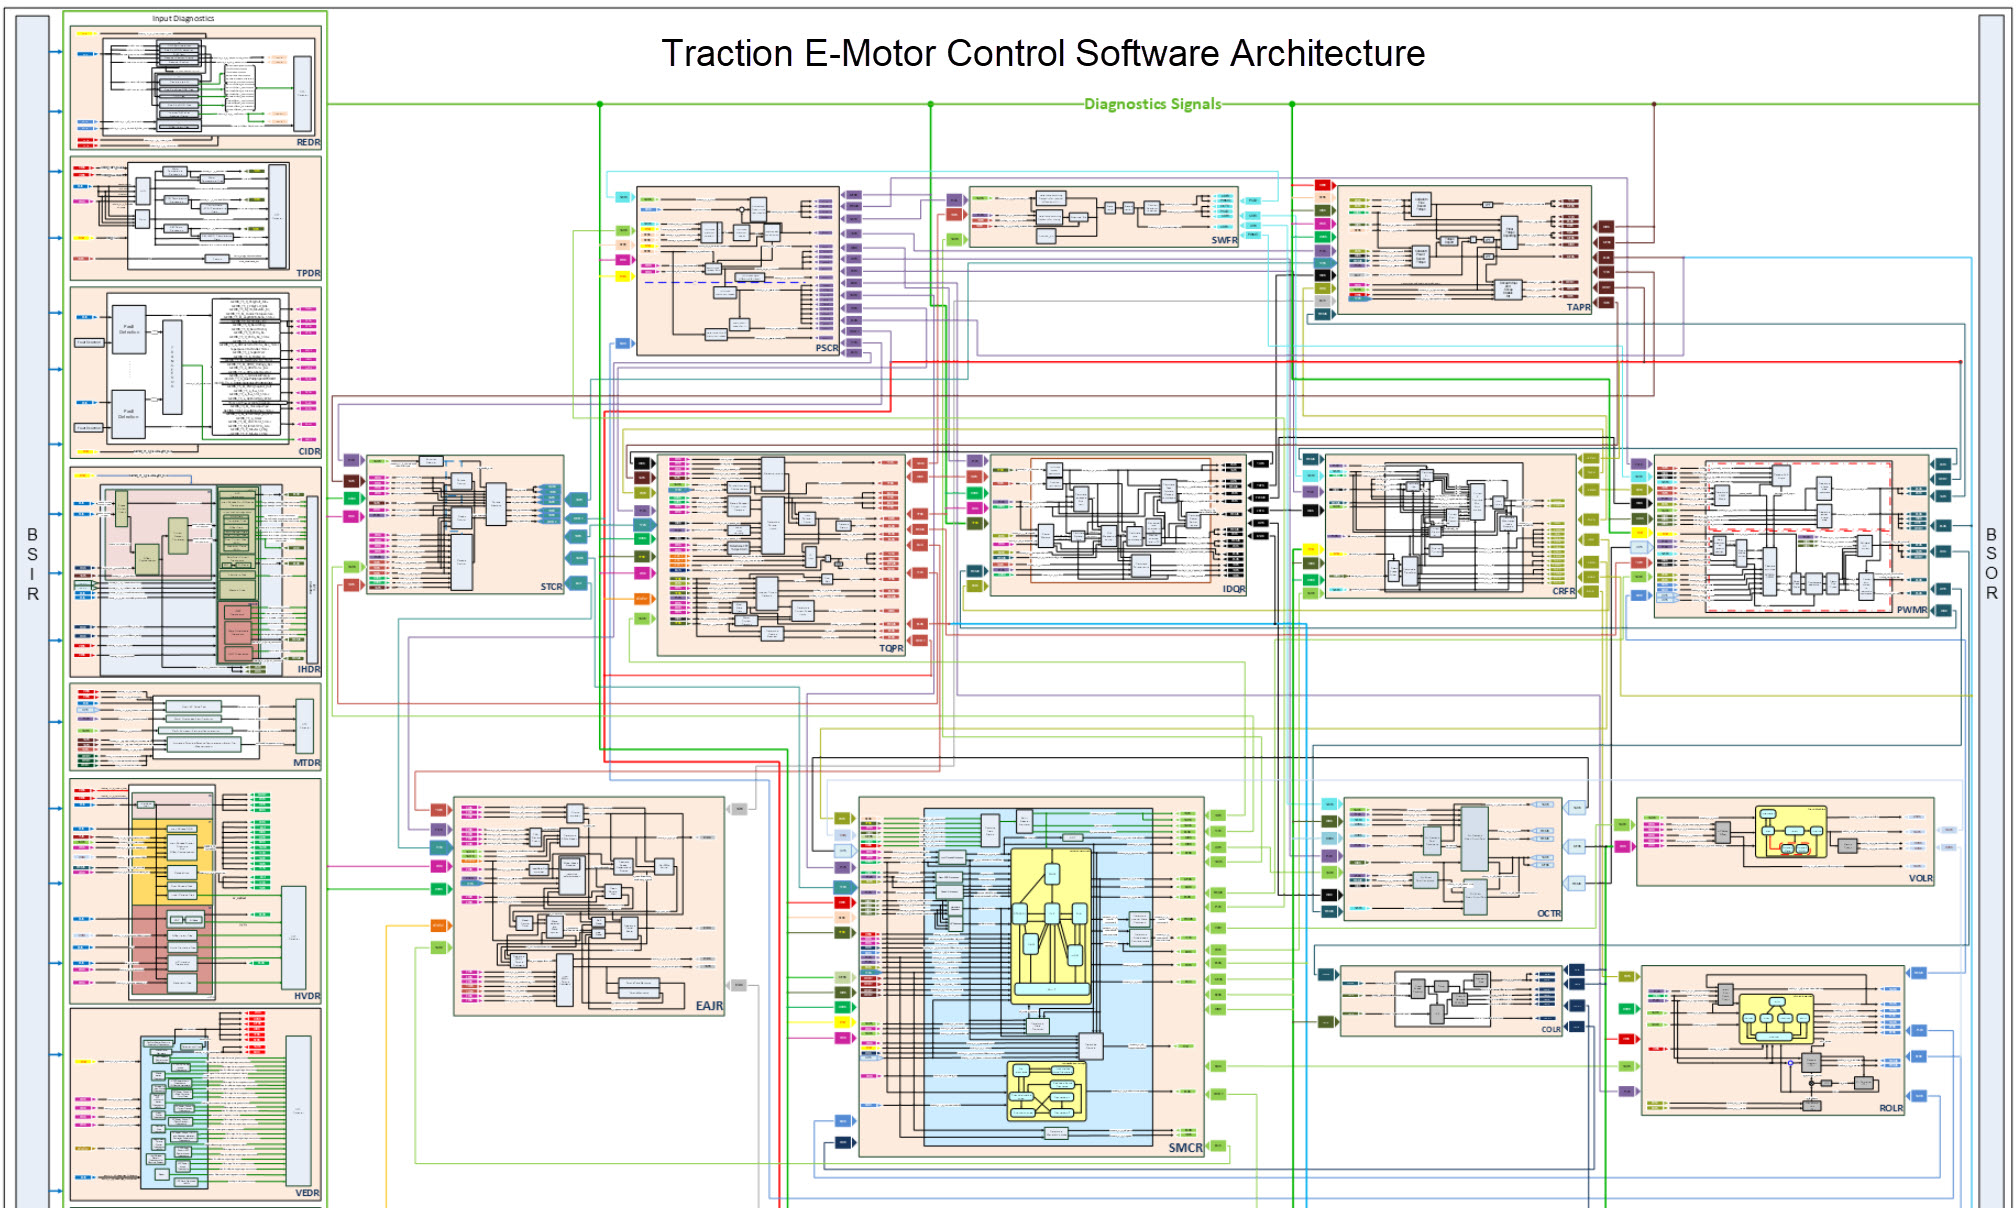

## 1.0 Requirements Definition

[Open](matlab:slreq.open("TractionEmotorRequirements.slreqx");) the **Requirements Editor** for the **"TractionEmotorRequirements.slreqx"** document. This requirements document includes two main sections: **FunctionRequirements** and **TestRequirements**, both authored directly within the Requirements Editor.

Under **FunctionRequirements**, each child requirement corresponds to a specific component implemented in the architecture model.   [Open](matlab: open ("TractionEmotorSoftwareArch_DataBus.slx")) the architecture model **"TractionEmotorSoftwareArch_DataBus.slx"**, then return to the Requirements Editor to view the **“Implemented by:”** links for each child requirement. These links connect directly to the corresponding components within the architecture model.

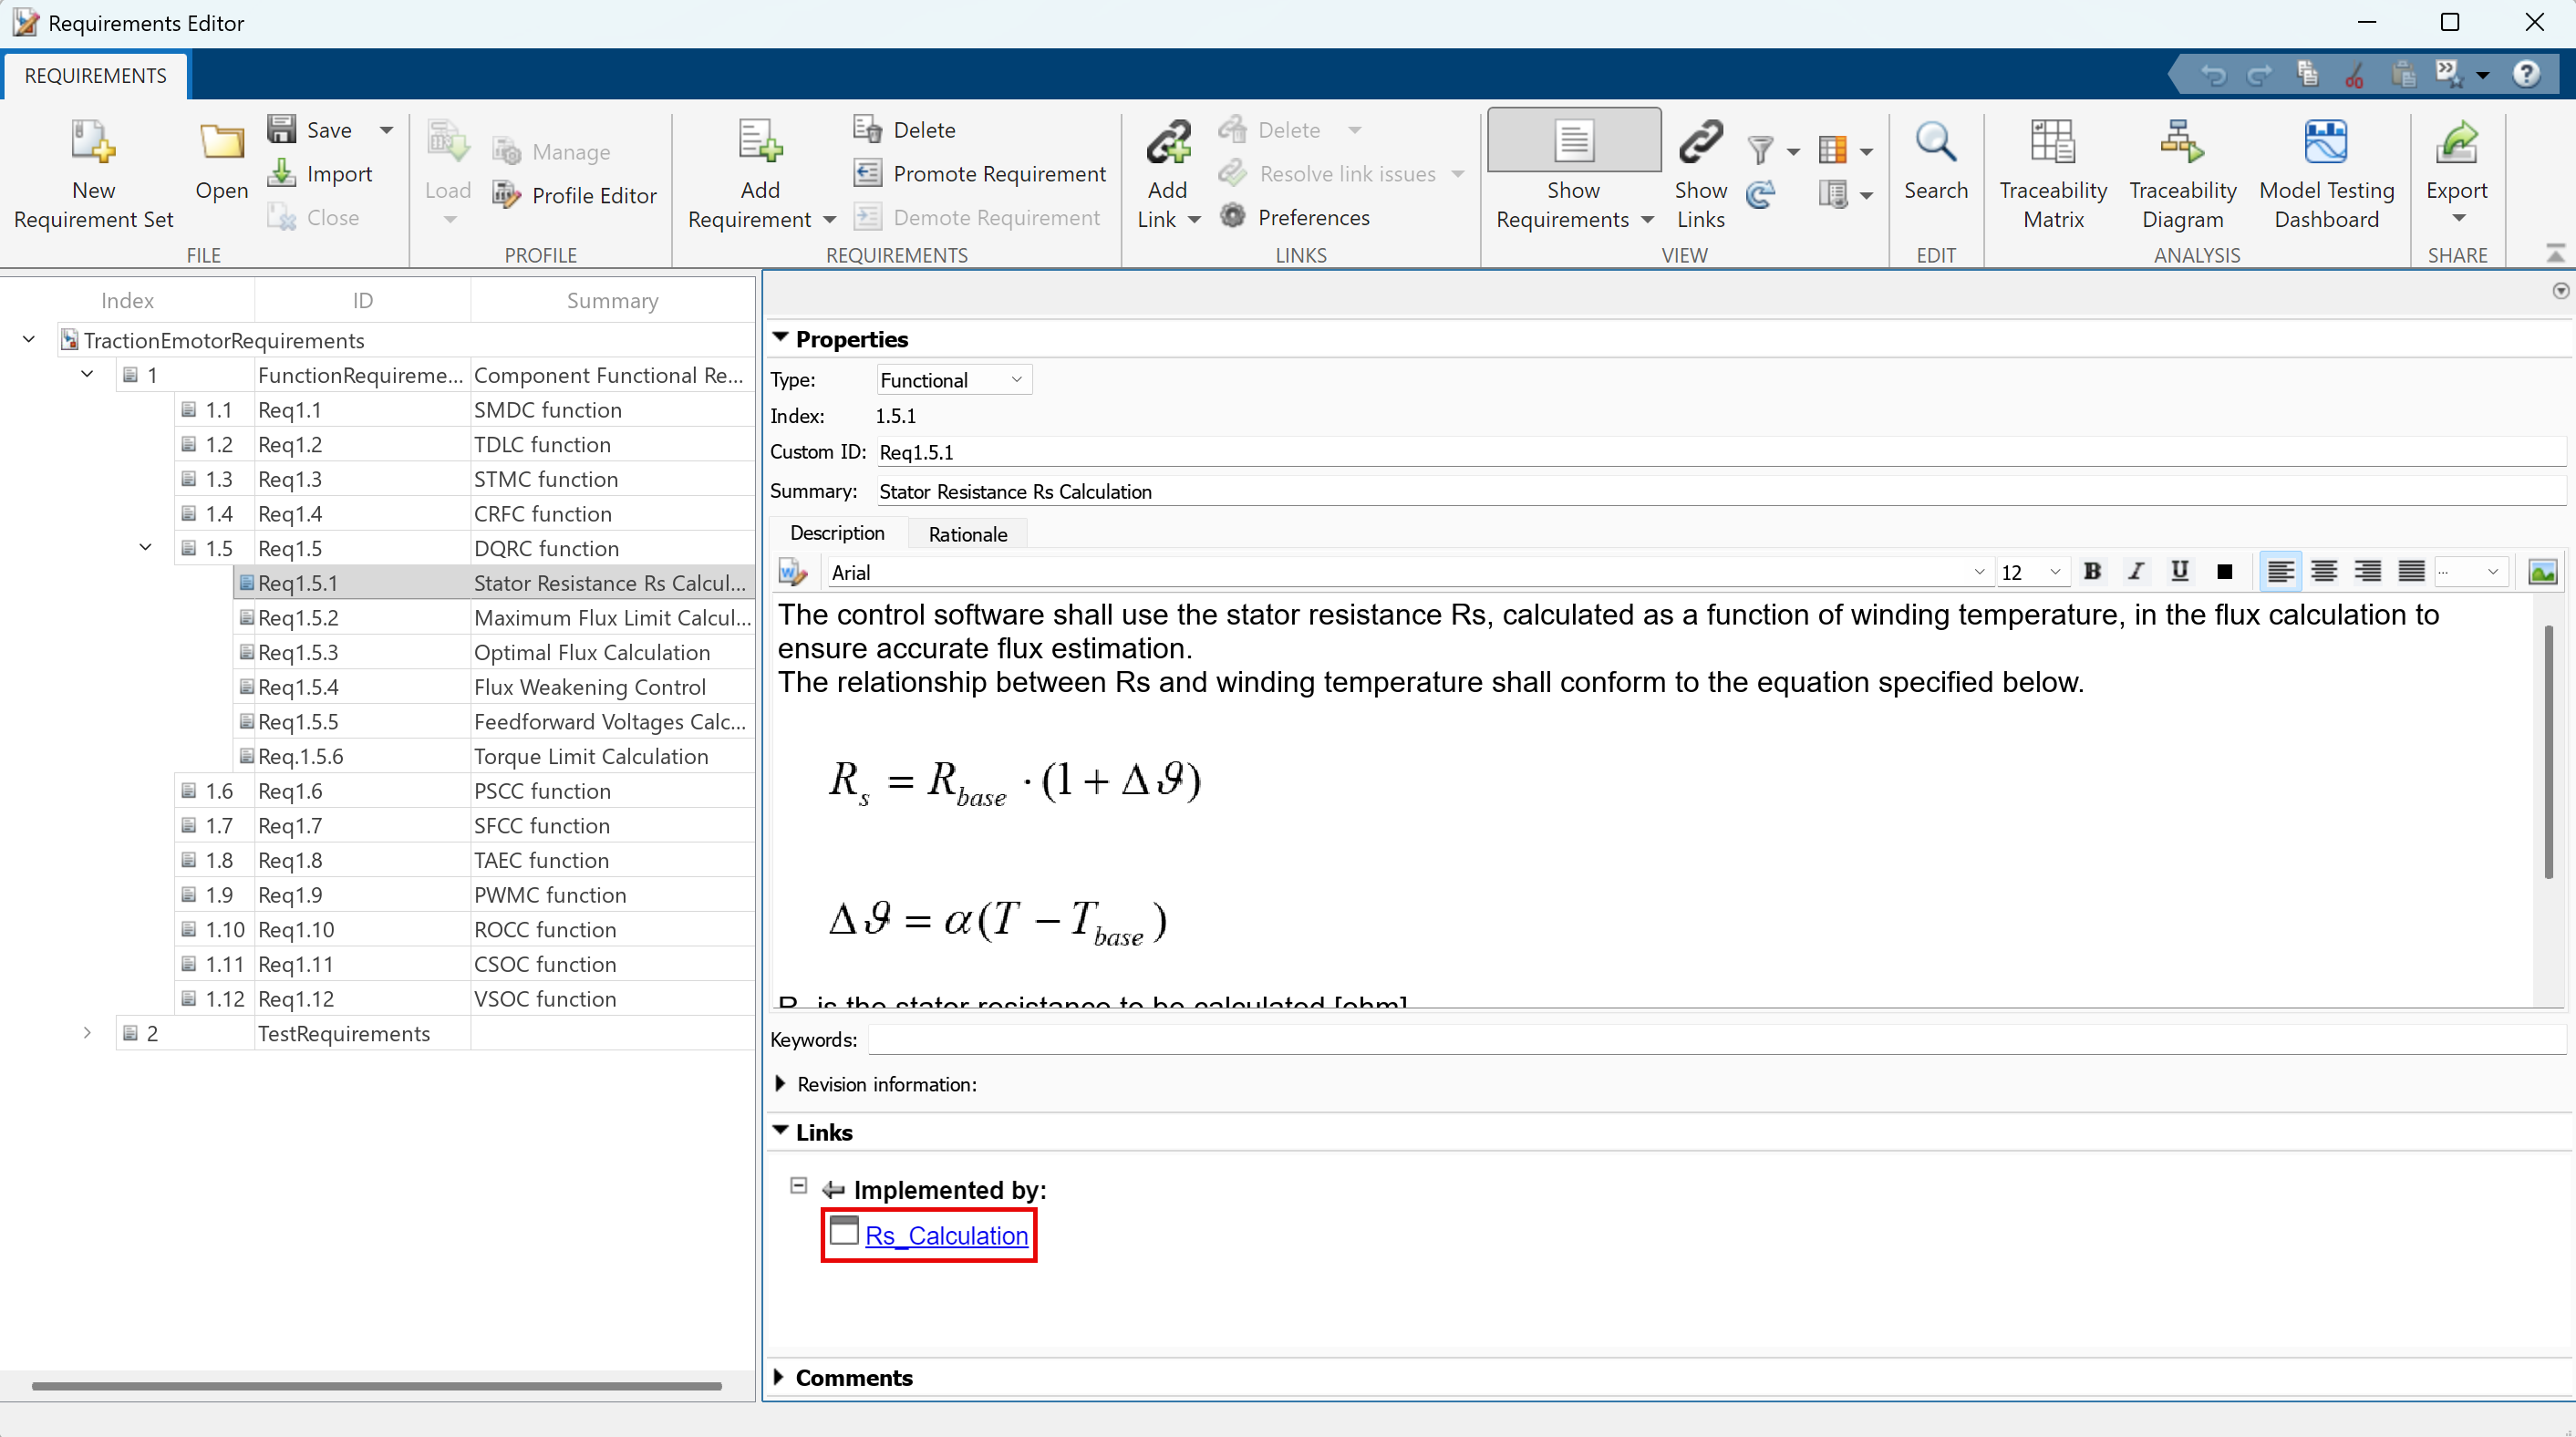

Navigate to Section 2: TestRequirements.  Notice that both child test requirements are verified by .   This traceability link will be resolved once you load the Simulink Test file. ([Open](matlab: open("exampleTest.mldatx")) exampleTest.slmx)

Notes: 

- Requirements can also be directly imported from [3rd party tools](https://www.mathworks.com/help/slrequirements/ug/import-requirements-from-third-party-tools.html).

- You can generate requirements report by clicking Export -> Generate Report in the Requirements Editor tool strip.

## 2.0 Traction e-Motor Control Software Architecture Overview

Two versions of this motor control software architecture model were created: one with interfaces defined by data buses, and another using individual signals. Both architecture models contain the same algorithm components listed below:

Algorithm Components:

**SMDC**: System Mode Determination Component

**STMC:**Speed/Torque Mode Component

**TDLC: **Torque Derating and Limiting Component 

**PSCC: **Position and Speed Calculation Component

**SFCC:**Switching Frequency Control Component

**TAEC: **Torque Achieved Estimation Component

**DQRC:**DQ Reference Current Calculation Component

**CRFC:**Current Regulation and Feedback Component

**PWMC:**PWM Generation Component

**ROCC: **Resolver Offset Calibration Component

**CSOC:**Current Sensor Offset Calibration Component

**VSOC:**Voltage Sensor Offset Calibration Component

In addtion, the arthicture model also includes 6 input diagnostics components, which are: CAN Interface Diagnostics Component(**CIDC**), Resolver Error Diagnostics Component(**REDC**), System Temperature Diagnostics Component (**STDC**), Inverter Hardware Diagnostics Component(**IHDC**),Motor Faults Diagnostics Component(**MFDC**),Vehicle Status Diagnostics Component(**VSDC**).

### 2.1 Reference Component

[Open](matlab: open ("TractionEmotorSoftwareArch_DataBus.slx")) the architecture model "**TractionEmotorSoftwareArch_DataBus.slx**". Notice that each of the 12 algorithm components in this model is implemented as a reference component. These reference components contain their own subcomponents, defined hierarchically beneath them.

Similar to Simulink Reference models, reference components enhances modularity and scalability, and can be directly mapped to Simulink behavior models or AUTOSAR architectures. 

Among the 12 algorithm componets, only the DQ Reference Current Calculation Component(DQRC) includes detailed, linked Simulink behavior models for its subcomponents, serving as an example of how behavior model linking is represented in the architecture. Details of these behavior models are discussed in Chapter 3.0.

### 2.2 Profiles and Analysis

Custom stereotypes and properties are added for the architecture model, which makes the architecture diagram more expressive with custom color and line styles, allowing engineers to extend the modeling language to represent domain specific concepts. For example, all diagnostics data buses are represented by "dotted" connectors while algorithm data buses have solid ones. See below.

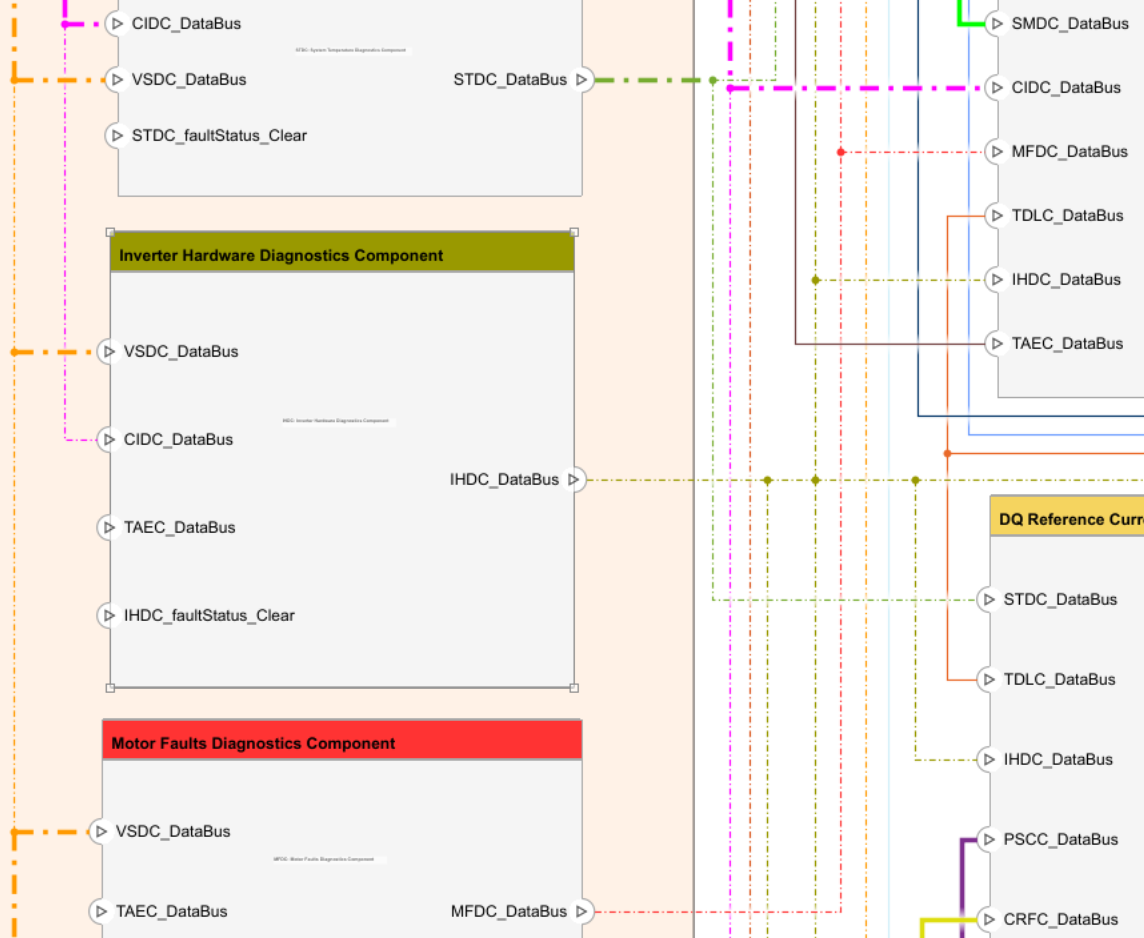

Enginers can create query-based filtered views of the architecture model to expose components of interest. For instance, when signal "Inverter_status_cmd_100us" is corrupted, we can create a filtered view of all software components that would be impacted by this signal.  Simply add a COMPONENT FILTER and use the signal name in the criteria.  See below:

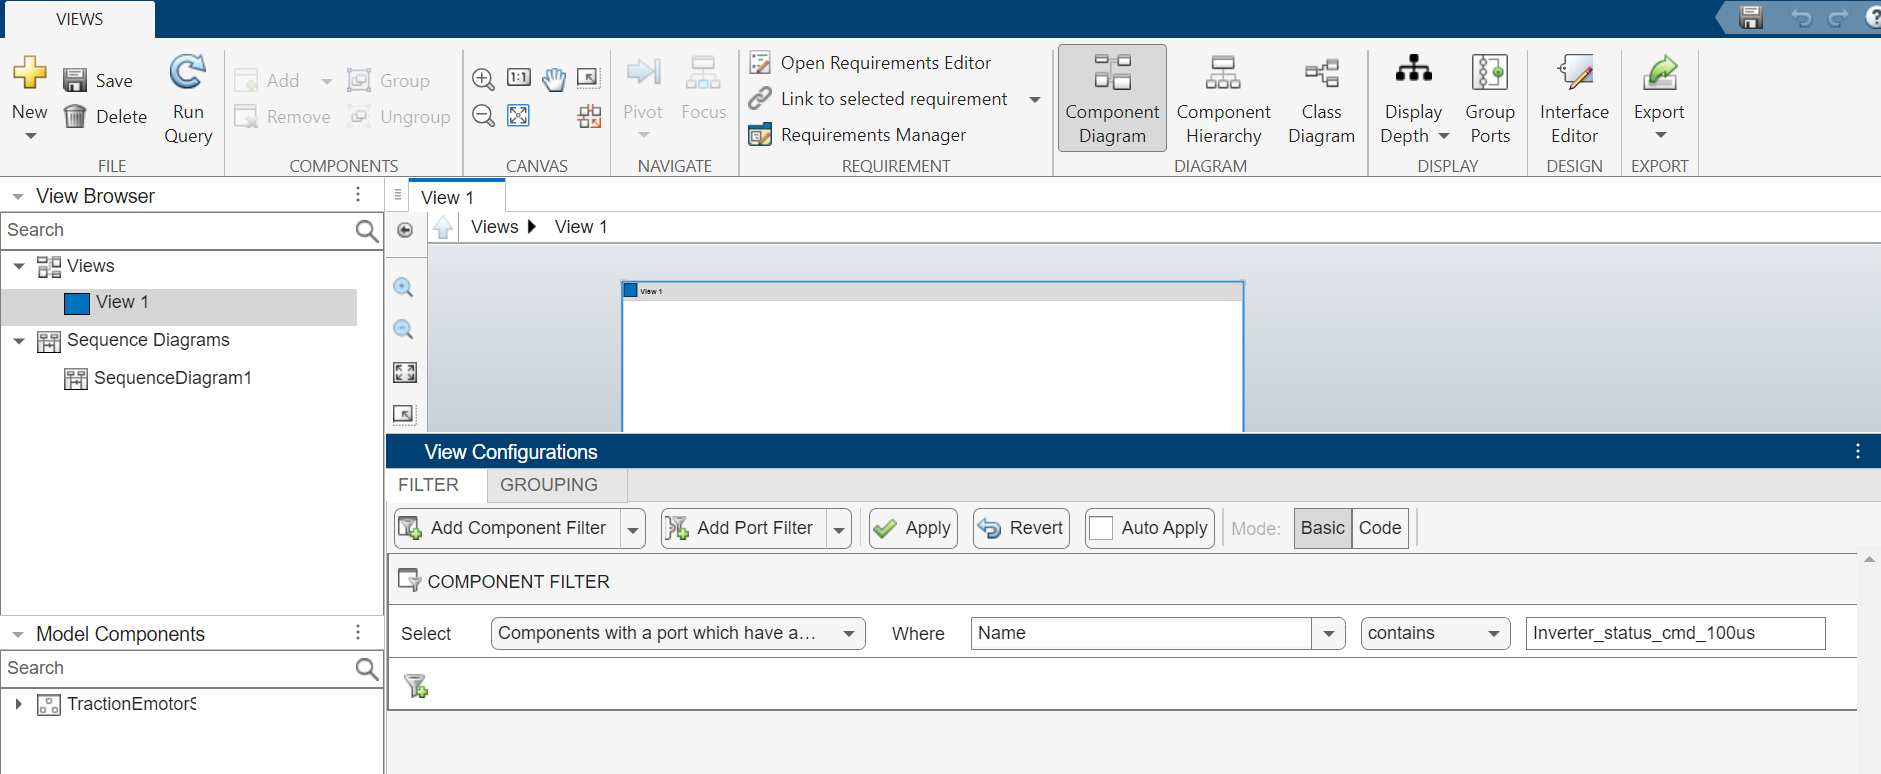

After clicking "Apply", you will get a filtered component view below:

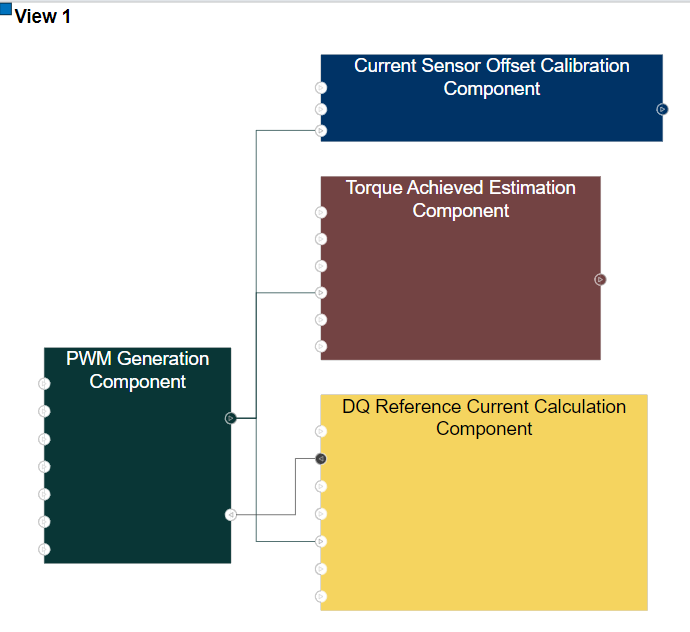

Additional properties can be defined through the Profile Editor, such as tagging components with attributes like **ASIL Level**, **Model Structural Complexity**, or **CAN Message Bandwidth**. These property tags enable easier filtering, visualization, and analysis of system aspects relevant to different stakeholders.

### 2.3 Component Interfaces

In System Composer, a component interface defines the structured data and communication patterns for ports, allowing you to manage data elements, value types, and physical interfaces between components in an architecture model.

Since component interfaces and Simulink buses have equivalent semantics, they can be converted from one to the other without loss of meaning or functionality.

Let's look at an example below:

1). Create a subcomponent under "CAN Interface Diagnostics Component" called "Clear Fault Memory", connecting VSDC_DataBus and CIDC_DataBus to it as input and output port, respectively. 

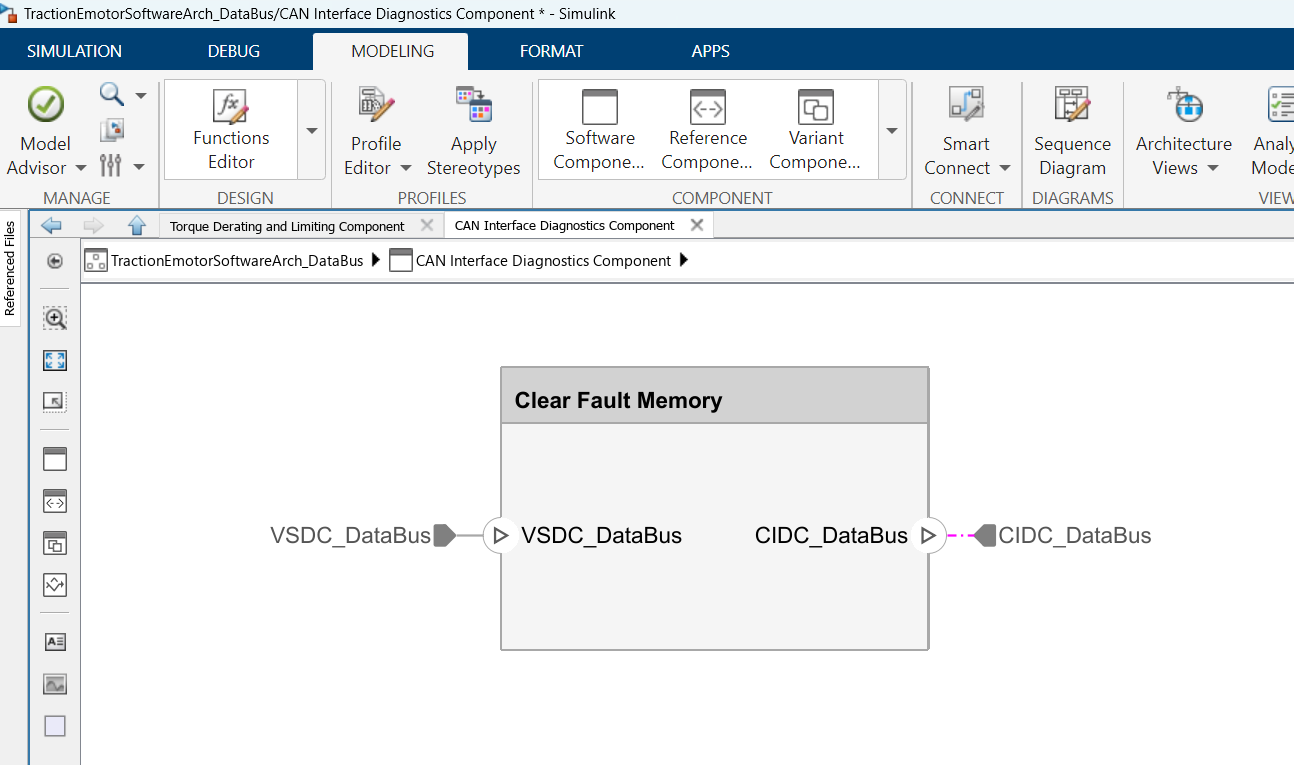

2).  Right click "Clear Fault Memory" and select "Create Simulink behavior".

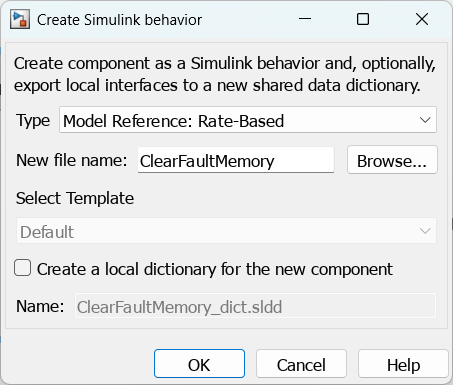

3). After clicking "OK", you'll see a Simulink reference model being created.  Double click VSDC_DataBus port and you'll see the Simulink bus object definition for VSDC_DataBus,which is automatically converted from the interface definition saved in TractionEmotorSoftwareArchInterfaceData.sldd. 

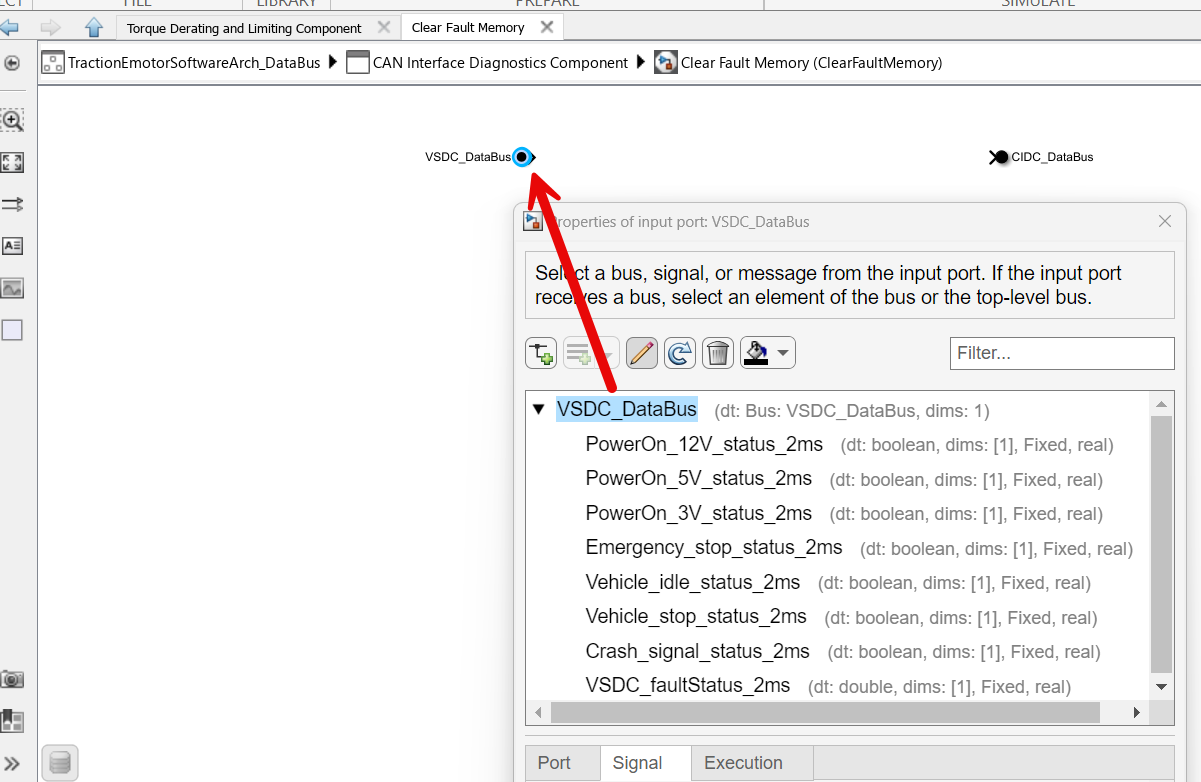

A software architecture template also supports client/service interfaces for service-oriented architecture. See [Authoring Client Server Interfaces in System Composer](https://www.youtube.com/watch?v=0eIymqVoZLs).

### 2.4 Architecting for Functional Safety

One of the main focal points in part 6 of ISO 26262 is the workflow for developing, validating, and verifying software units. Software units are intended to be the smallest testable parts of an application that must be individually tested for proper operation. Requirements will be mapped to and/or within these individual software units, and requirements-based test cases will be built to exhaustively test the software unit. 

Model referencing is widely adopted as the standard approach for structuring software units in functional safety applications, ensuring ease of verification and robust unit-level testing. When creating a software architecture, the component that is linked to Simulink behavior is essentially a reference model wrapped in an architecture context, with extra metadata(interfaces, stereotyps, allocaiton, etc.), See "3.1 Simulink Behavior for DQRC Component".

ISO 26262 has five distinct safety levels (Quality Management [QM], and ASIL A–D) that can be used to classify systems, or components based on their functional safety aspects. Each component in the software architecture can have its own ASIL level which leads to different develop, validation and verification requirements. Engineers can manage ASIL across the architecture by attaching, propagaing the tracking ASIL information throughout the architetural model,enabling better compliance with ISO 26262 processes.

Practical steps for ASIL management in the software architecture model:

## 3.0 Simulink Behavior Models

### 3.1 Simulink Behavior for DQRC componnet

An algorithm model has been developed for the DQRC component, which is composed of six subcomponents. Each component is linked to a Simulink behavior model that has addtional model data saved in model workspace. The detailed implementation requirements are documented in the Requirements Editor. 

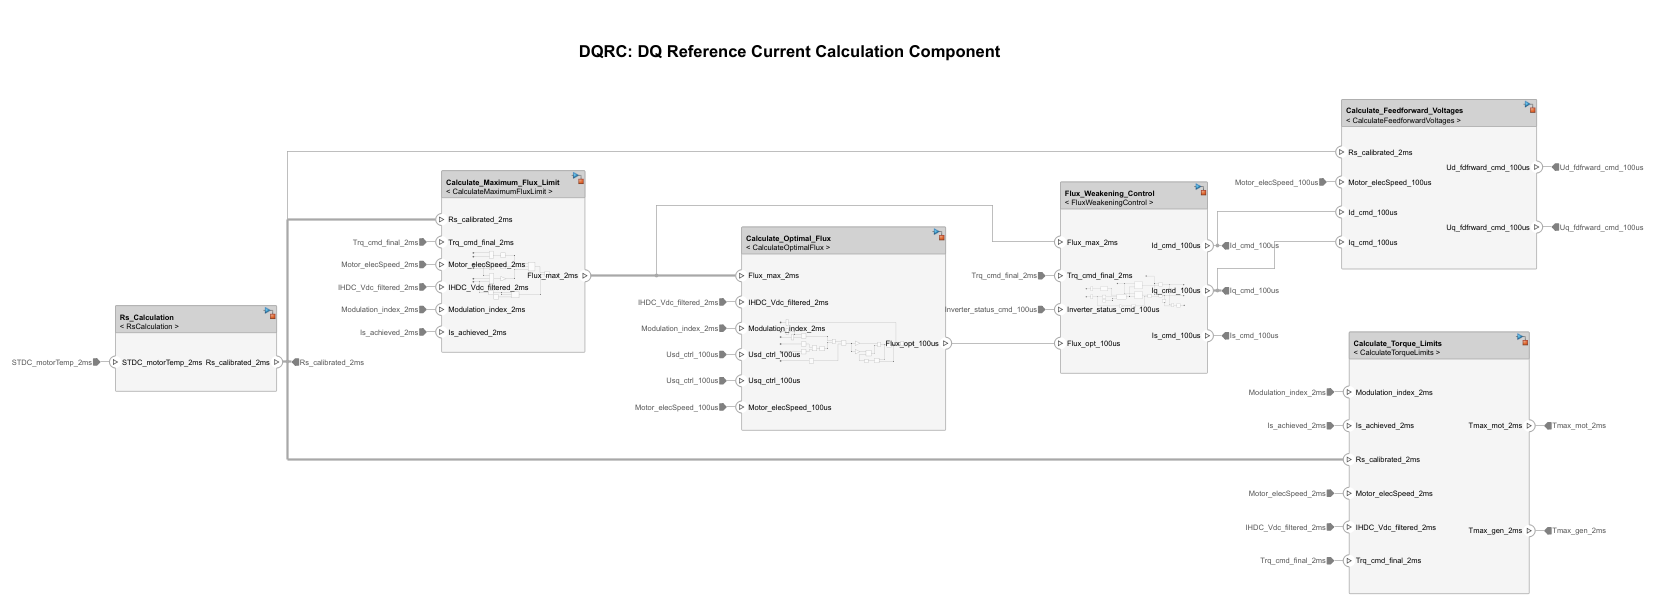

### 3.2 Functions Editor 

Functions Editor is a feature of software architecture models in System Composer. 

You can use Functions Editor to:

- change the execution order of functions.

- change the update rate of functions.

When generating code, each software subcomponent in the Simulink behavior model is converted into functions as defined by the **Function Name** field in the editor. See below.

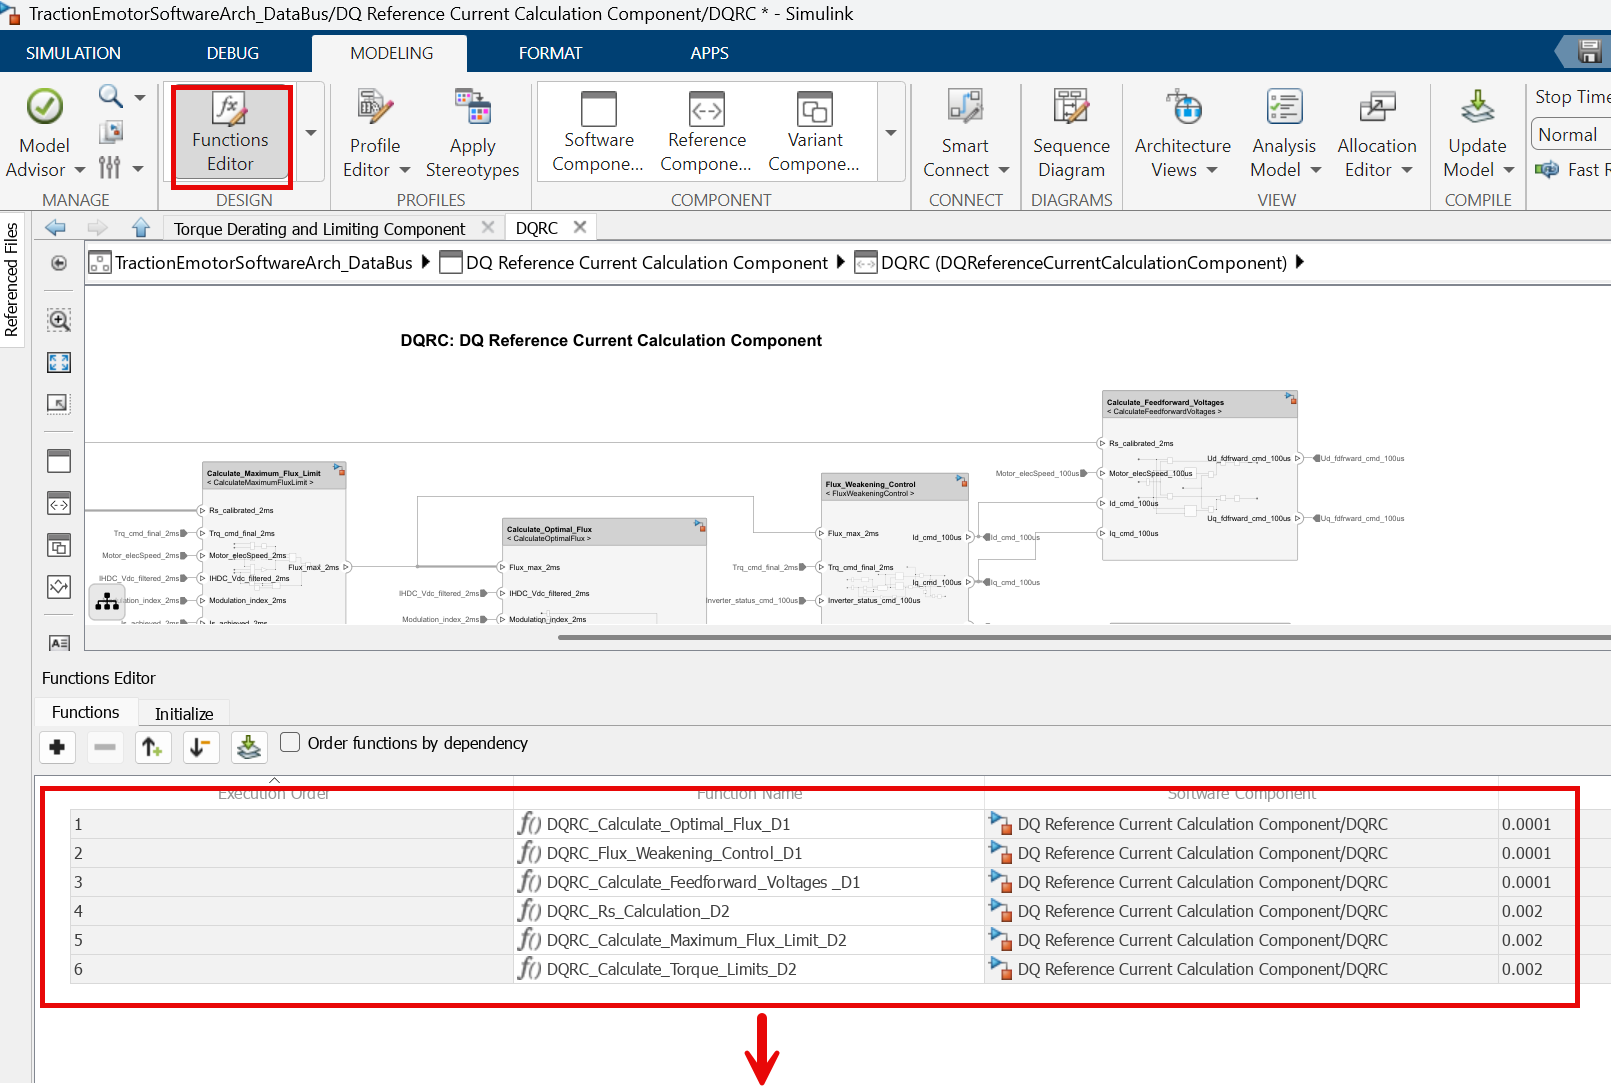

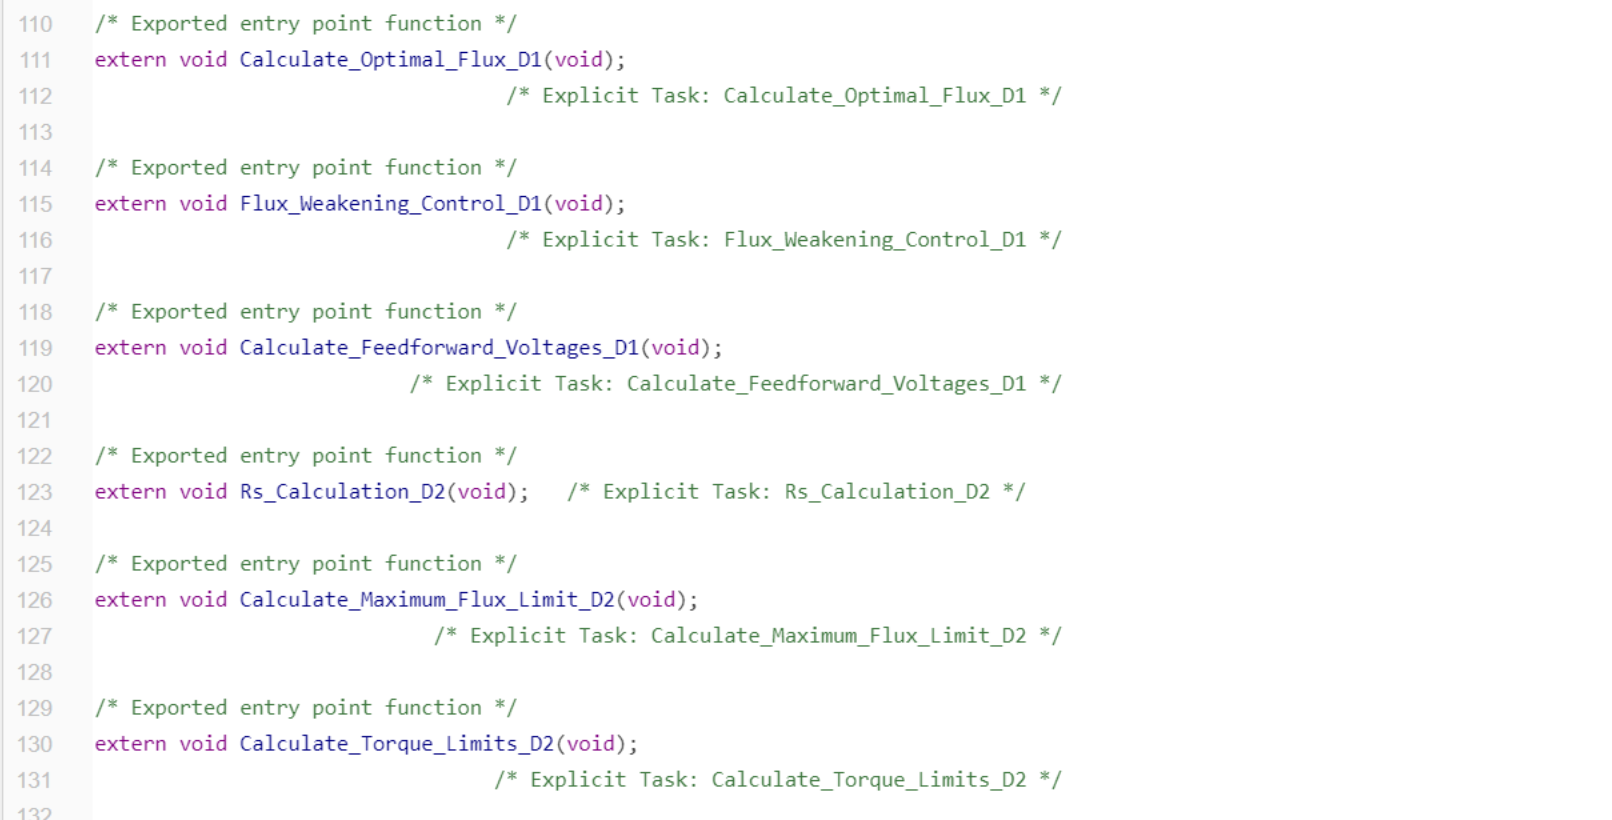

## 4.0 Testing Simulink Behavior Models Using Simulink Test

### 4.1 Author Tests

[Open](matlab:open('.\Tests\exampleTest.mldatx')) Simulink Test Manager and explore the TestSuite1.  Two separate tests have been created to verify the functionality of the Simulink behavior model **DQReferenceCurrentCalculationComponent.slx**.

- TorqueTransientResponseTest

For this test, you can refer to the detailed test requirements available in the associated **REQUIREMENTS** link. This is a torque step response test designed to verify that the current loop controller gains are properly tuned to meet the specified performance criteria. The criteria are evaluated using a custom assessment function, **TorqueTransientTest()**, whose source code is located in the **Tests** folder within the project directory.

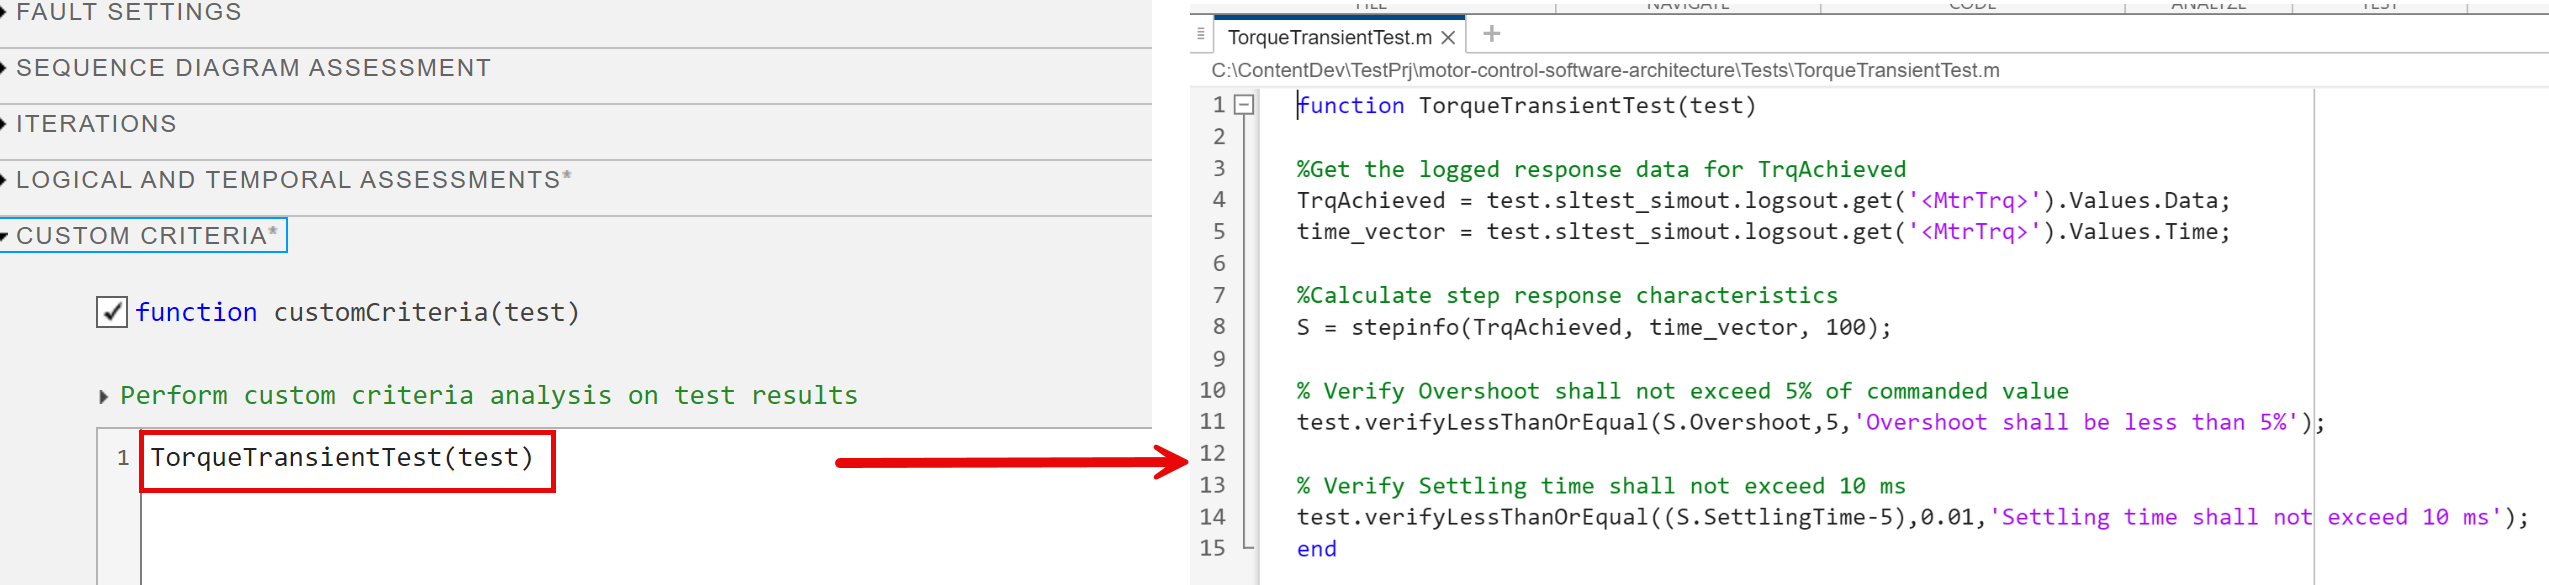

        2. TorqueAccuracyTest

In this test, a 100-second drive cycle serves as the input to the test harness. The drive cycle defines the e-motor drive’s **DC bus voltage** (in volts), **motor speed **(in RPM), and **torque command** (in Nm). The objective of this torque accuracy test is to determine whether the calibrations in the component under test (i.e., **DQReferenceCurrentCalculationComponent**) meet the required accuracy range.

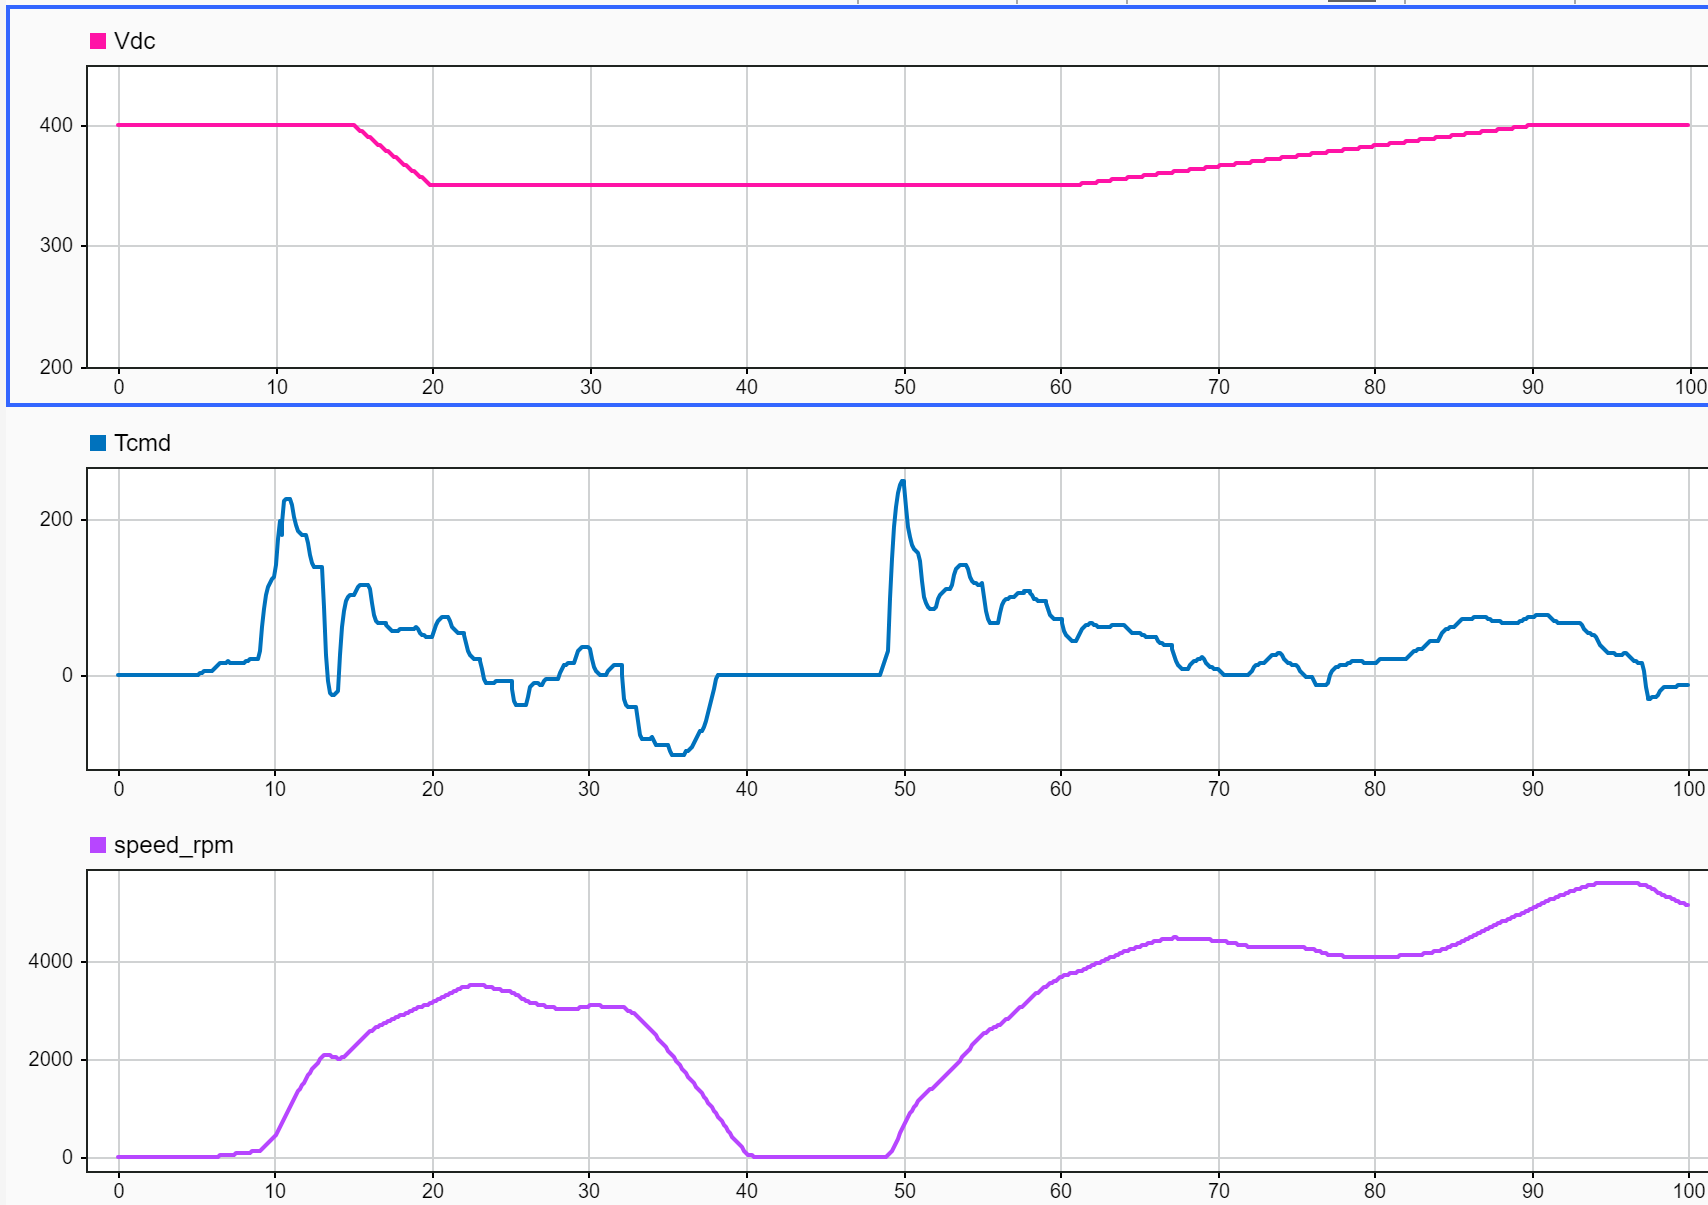

Throughout this drive cycle, the test harness simulates the **"DQReferenceCurrentCalculationComponent.slx"** model as part of a closed-loop simulation that includes a high-fidelity plant model. A **Test Assessment** block is added to the harness to evaluate the error between the commanded and achieved torque, verifying that the error remains within the range specified in the requirements.

### 4.2 Run Tests and Visualize Results

You can run each test individually by selecting it in the **Test Browser**, right-clicking, and choosing **Run**. Alternatively, you can run the entire **TestSuite1**. Once the tests have completed, you can view the results in the **Results and Artifacts** tab.

The **Simulation Data Inspector** is integrated into the Test Manager. For example, after a test completes, you can view the simulated results for the **Torque Accuracy Test** by selecting the corresponding **Sim Output**. See below.

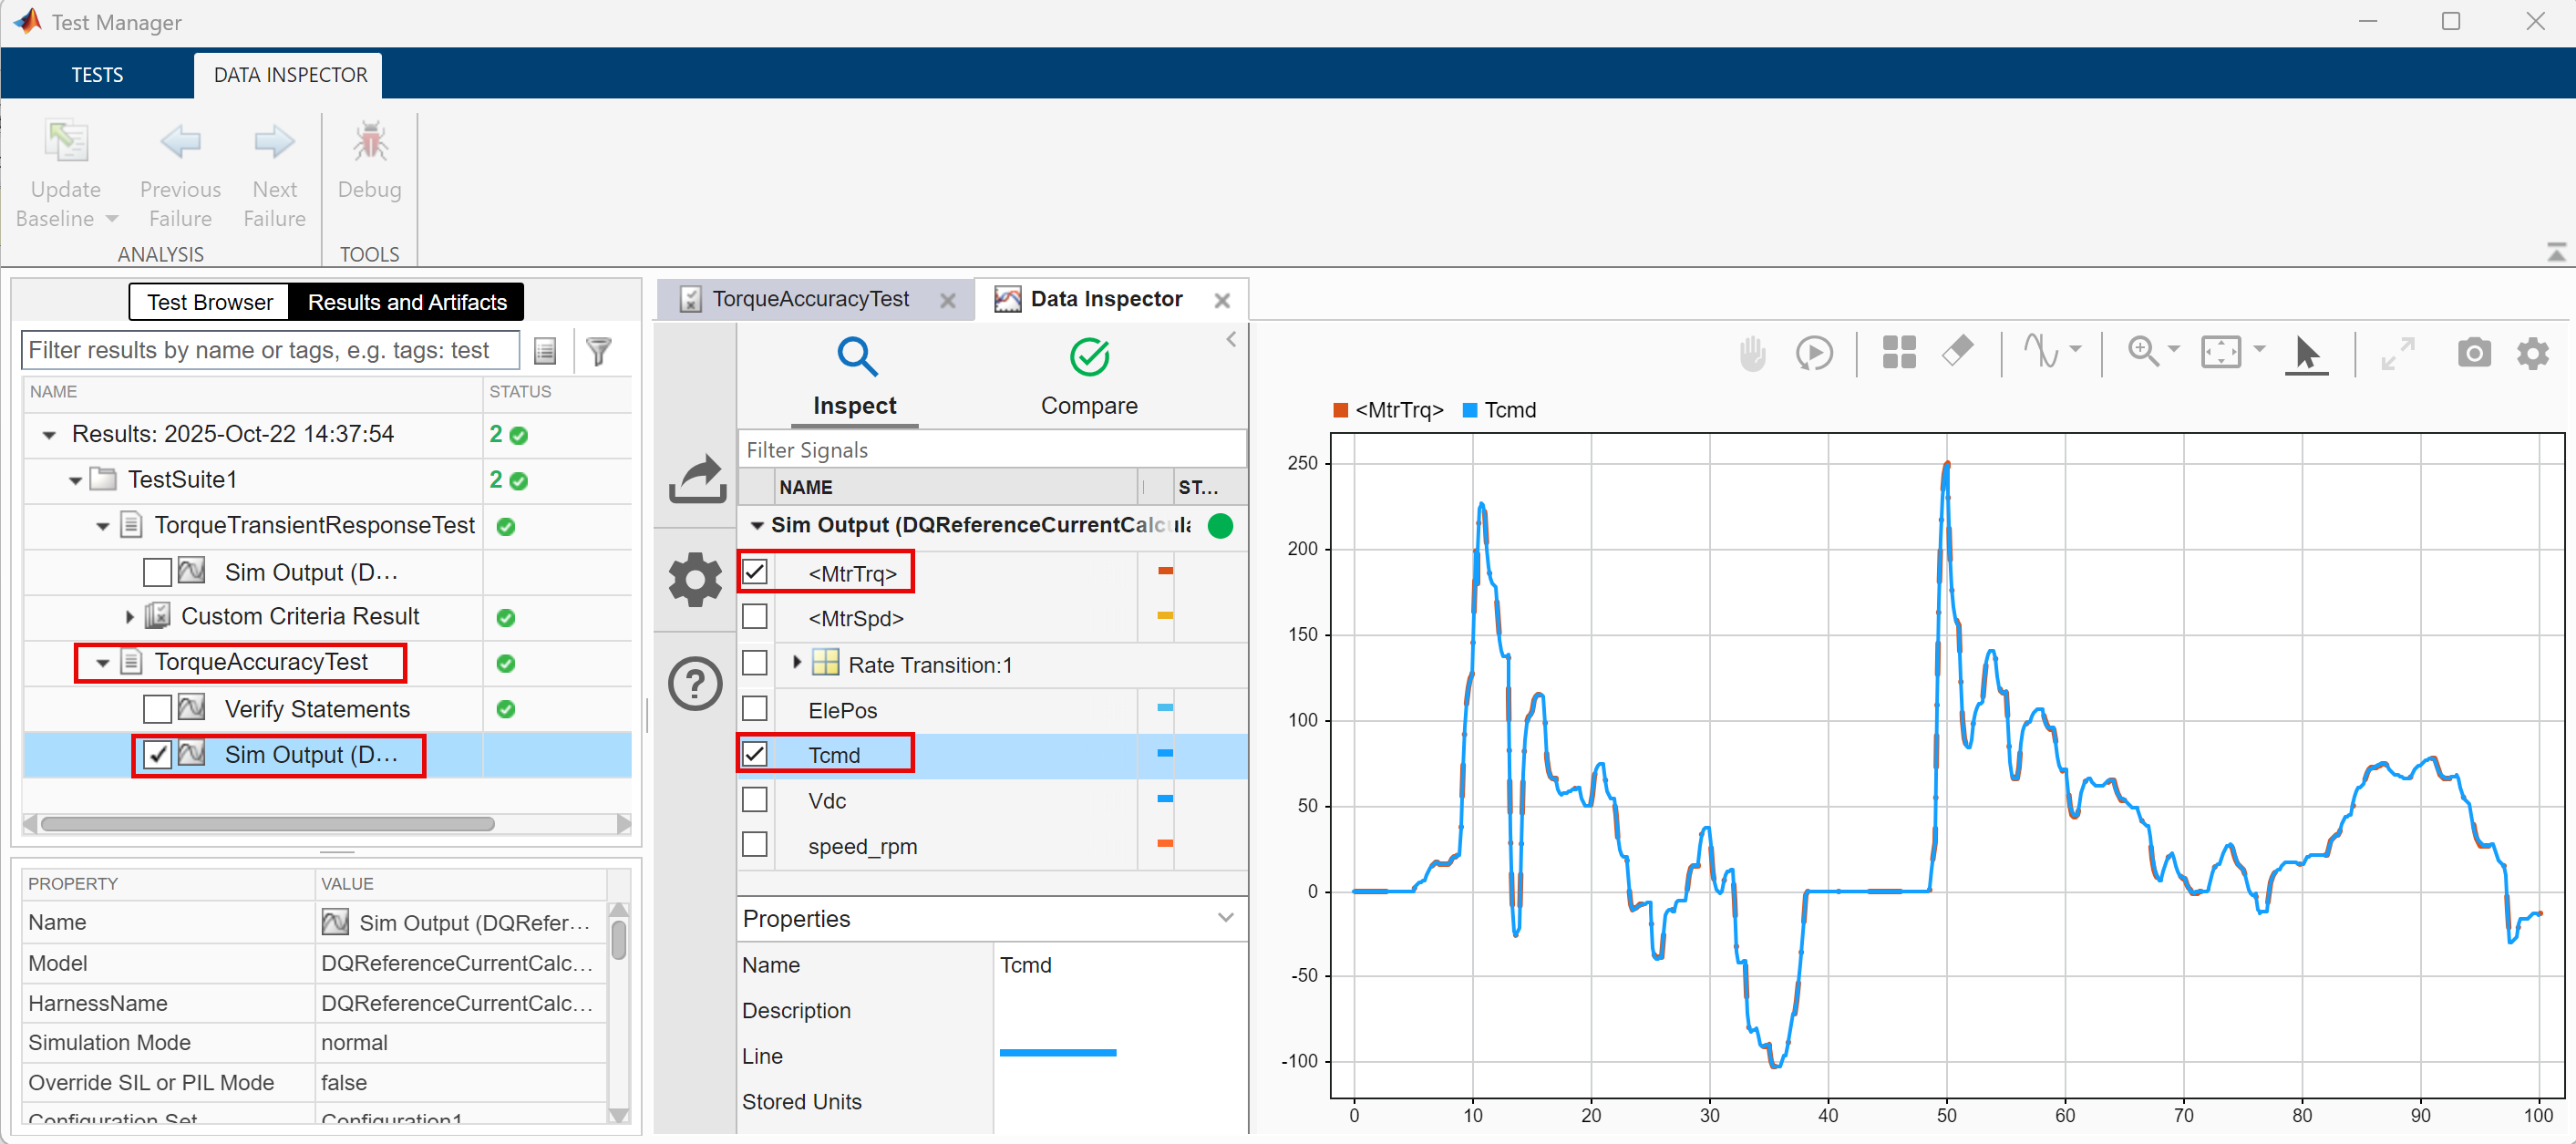

### 4.3 Integrate Test Results from an External File

For external tests, such as dynomometer tests for this traction e-motor, you can link test results and reflect test status in the requirements editor to create a digital thread.  

In order to establish this link, you need to create and register a custom document interface. 

myReqSet = slreq.open("TractionEmotorRequirements.slreqx");  % open the requirement file
rmi register custom_myexcelresults                           % register the custom doc interface

Create the struct that contains properties of the external test result.

externalSource.id = "Dyno_TorqueAccuracyTest";
externalSource.artifact = "externalresults.xlsx";
externalSource.domain = "custom_myexcelresults";

Find the requirement related to the link, then create the link between the test case "Dyno_TorqueAccuracyTest" and the requirement with the ID of "Req2.2".

requirement = find(myReqSet,Type="Requirement",ID="Req2.2");
link = slreq.createLink(requirement,externalSource);

View the verification status

updateVerificationStatus(myReqSet)

In Requirements Editor, the link appears in Req2.2 as a "Confirmed By" link type. 

### 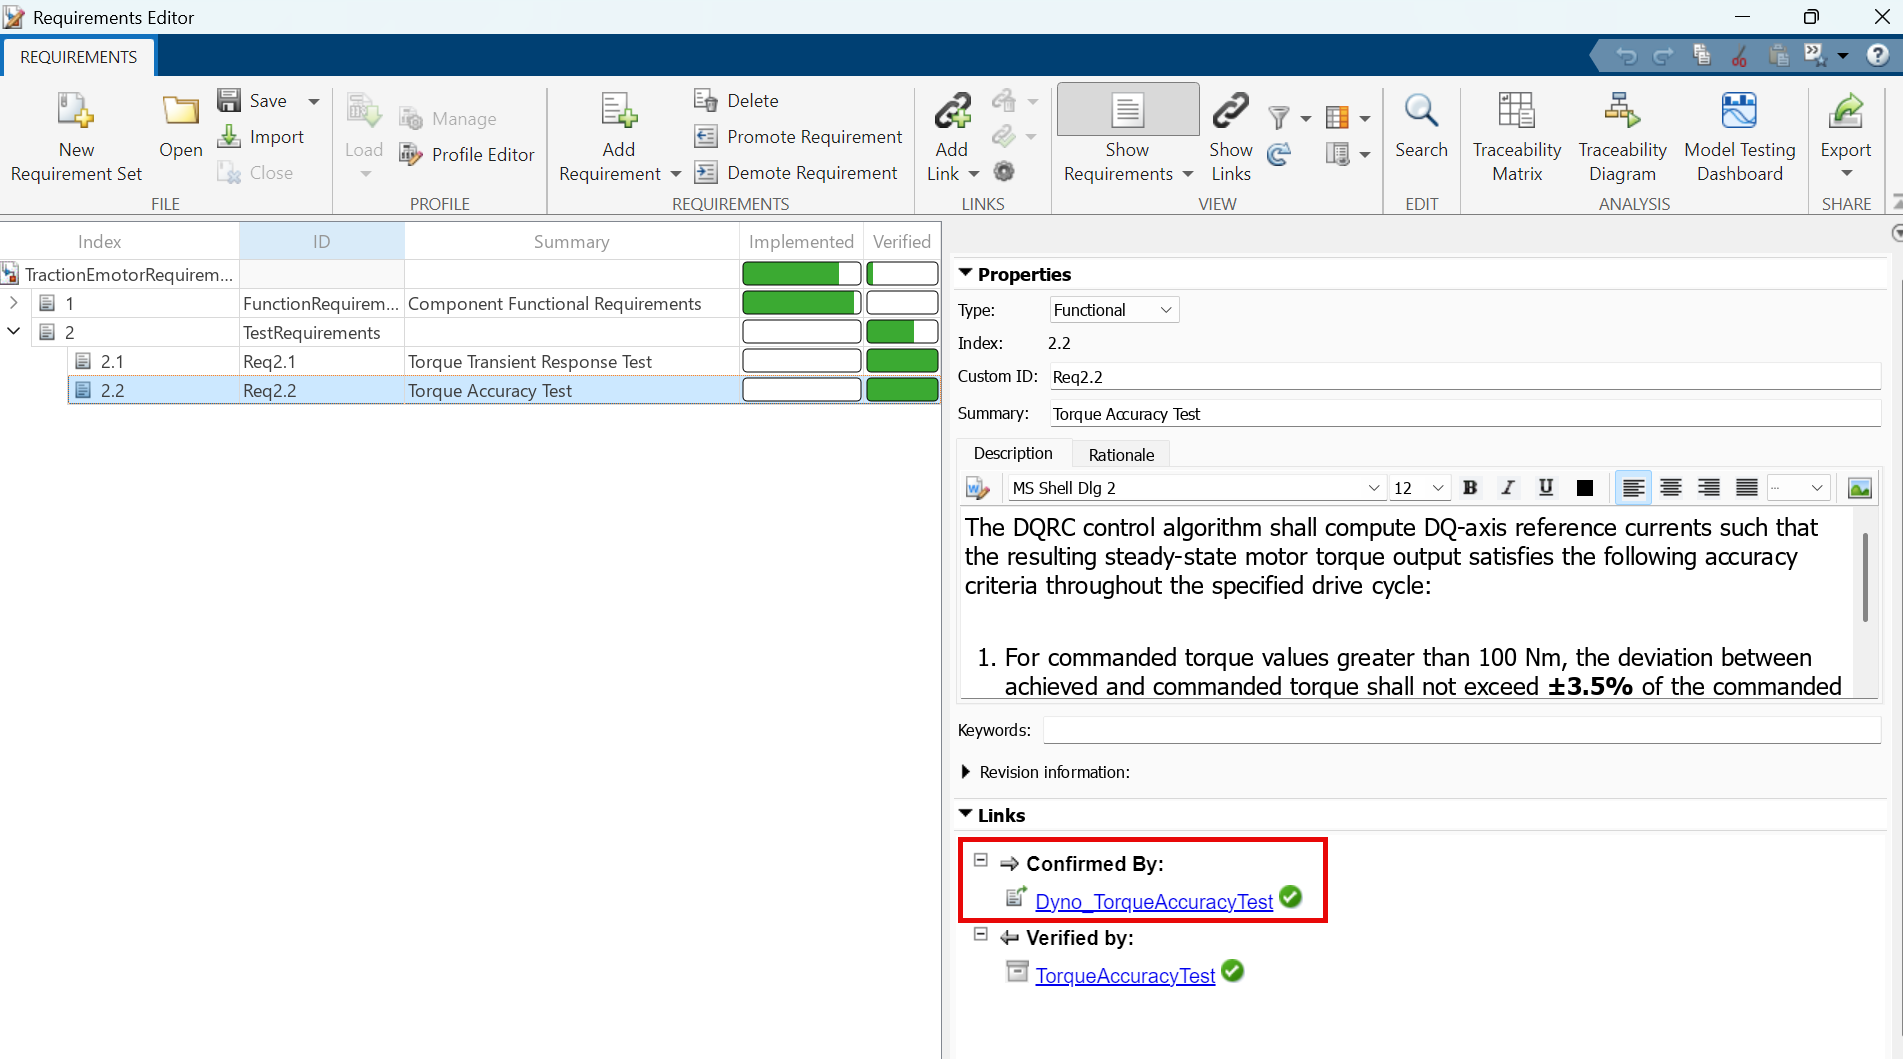

Use the unregister command to remove custom document interfaces you no longer need. 

rmi unregister custom_myexcelresults

### 4.4 Generate Test Report

Once the tests are complete, generating a report is as simple as clicking the **Report** button.

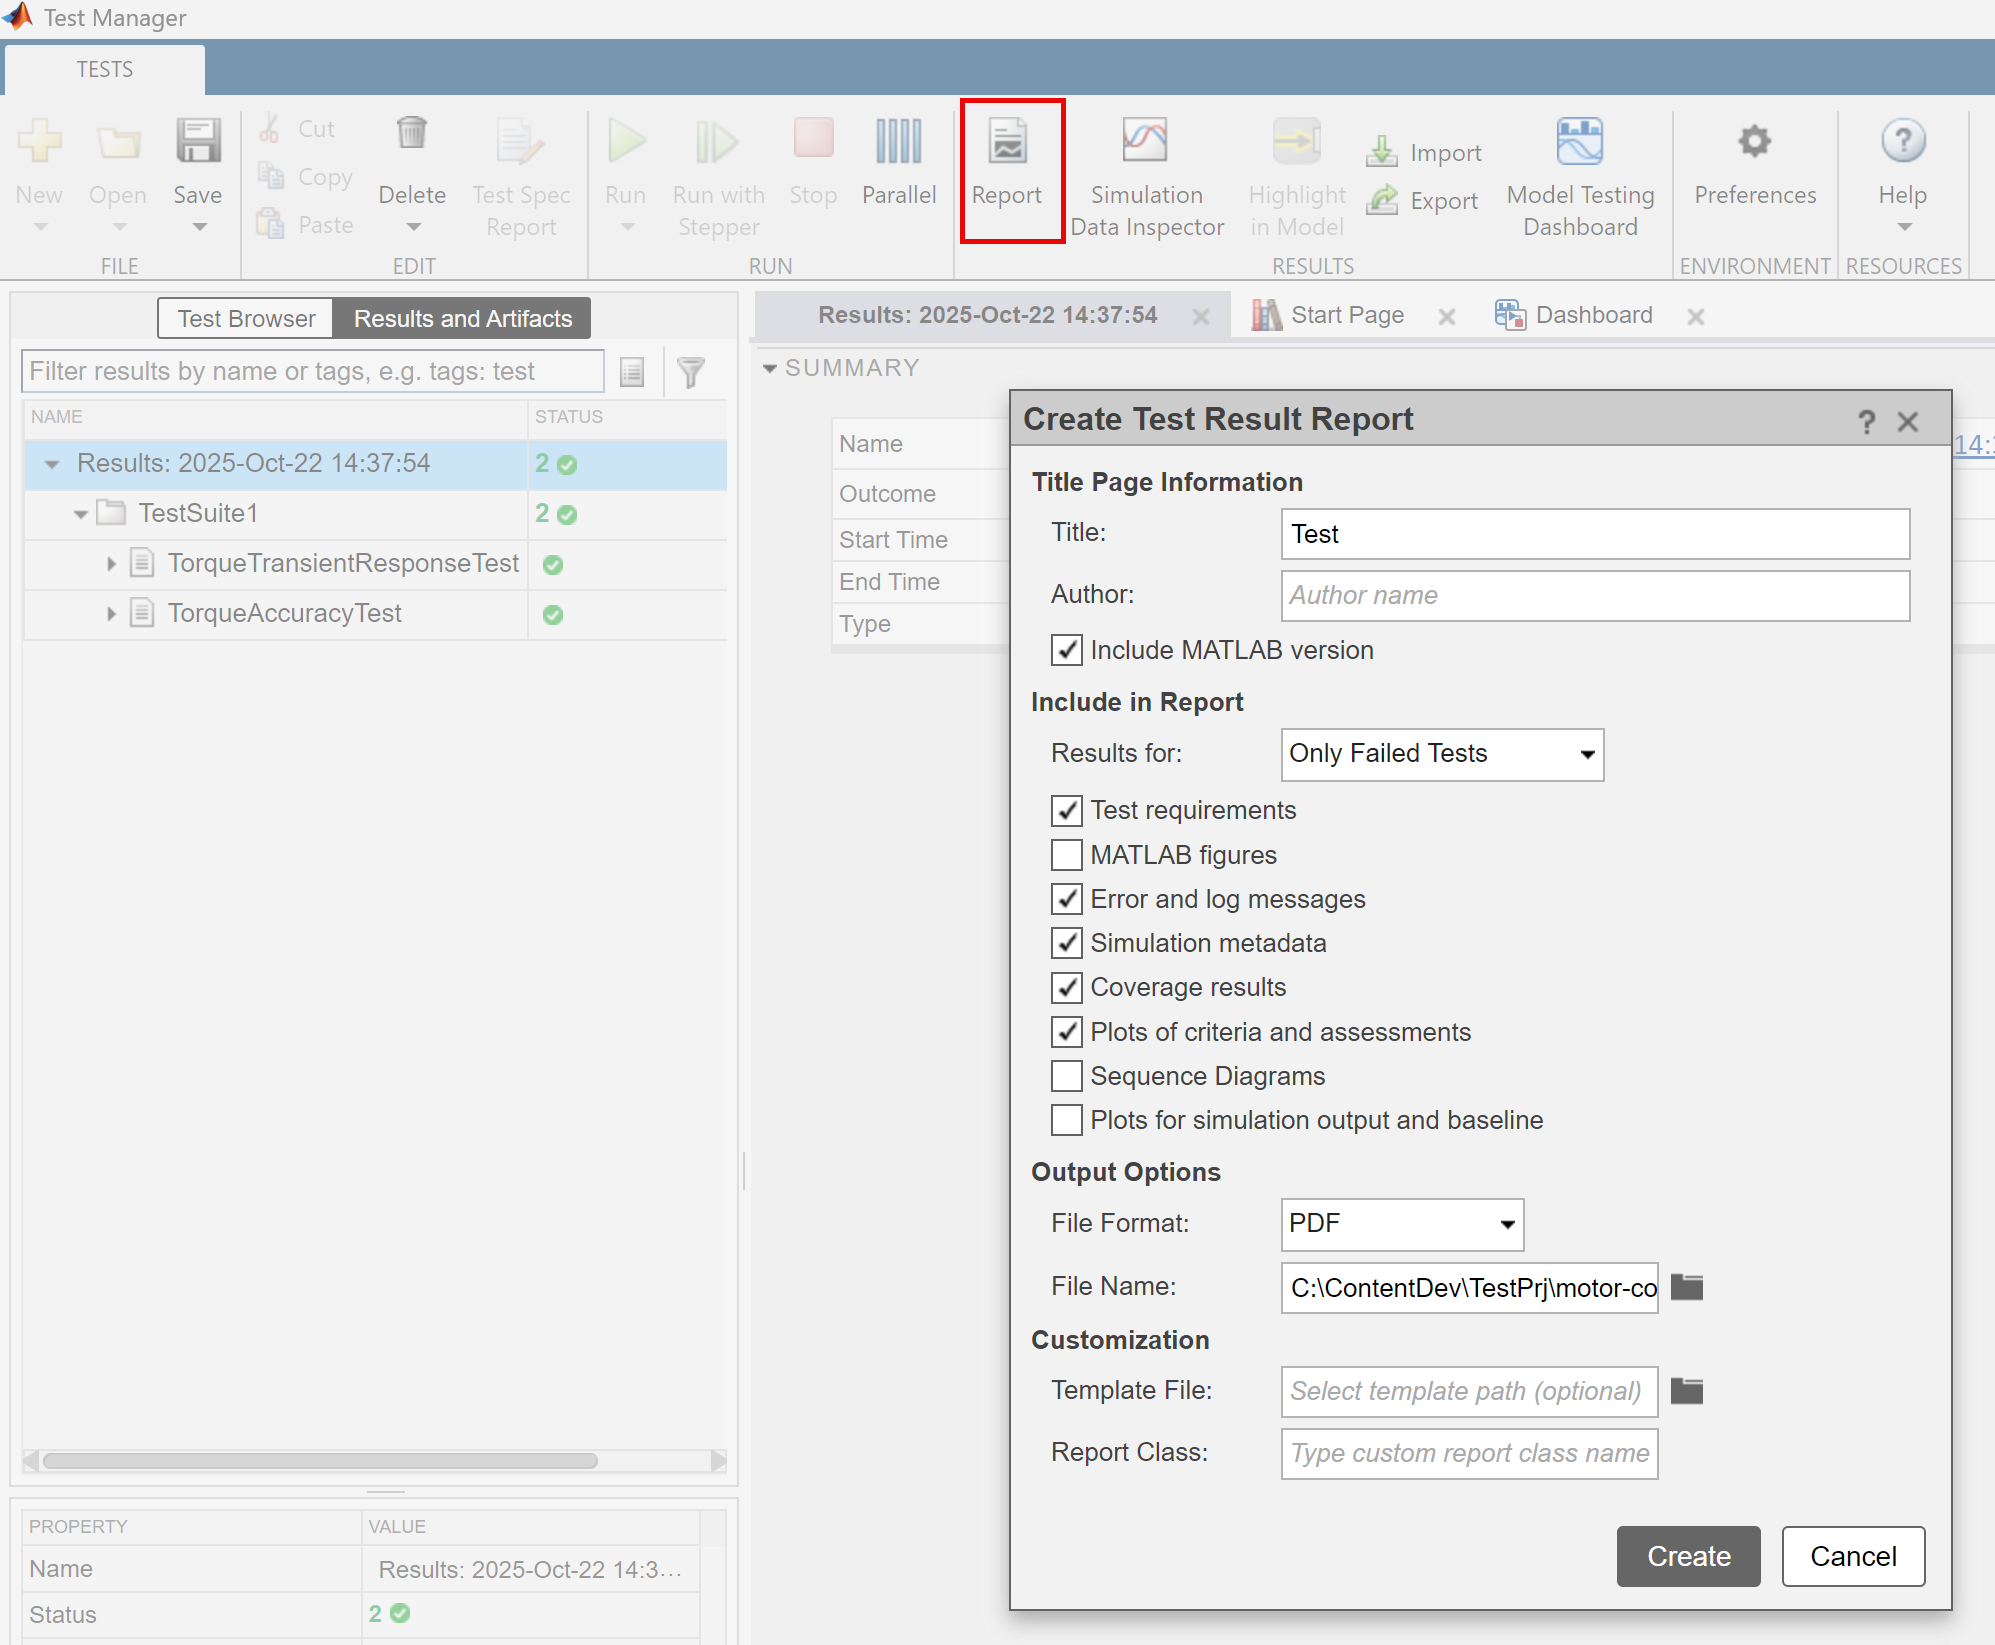

In summary, by leveraging **Simulink Test Manager**, engineers can create and run individual tests or organize and execute entire test suites automatically. In addition, the Test Manager enables linking requirements directly to tests or test suites, supporting a complete **digital thread**.

## 5.0 Generating Code for Behavior Models

All Simulink behavior models are organized in a dedicated folder within the project. In **processmodel.m**, a `codegenTask` is defined to generate code for all models located in the **SimulinkBehaviorModels** folder.

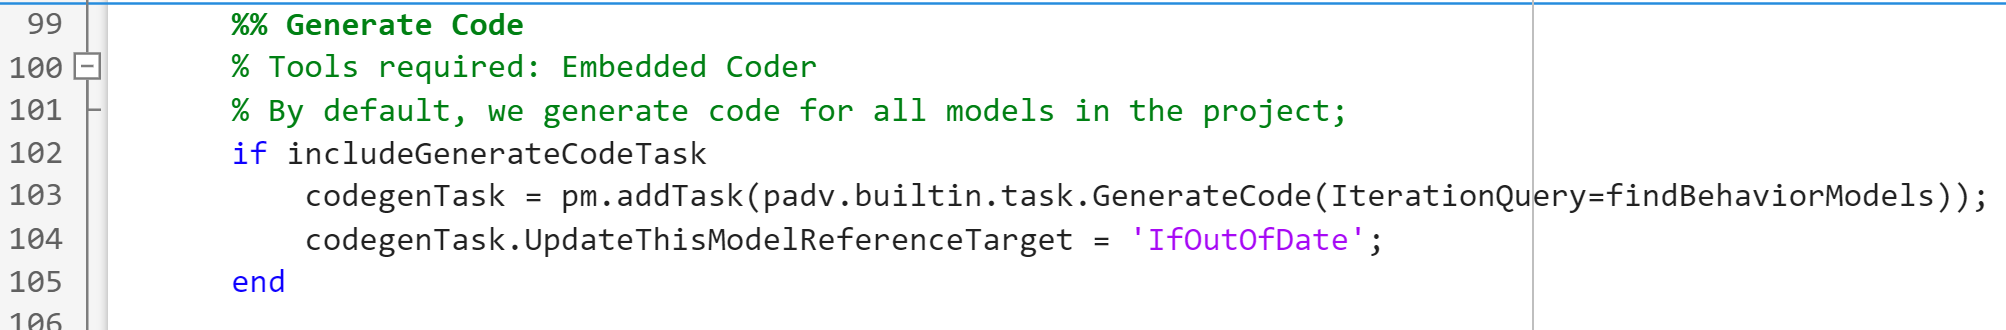

Before code generation, check the following fundamental code generation configurations for all behavior models:

- Solver: Fixed-step, discrete

- System Target file: ert.tlc

- Base data types (single or double)

- No continuous-time math blocks

You can also go through embedded coder "**Quick Start**" guide for each behavior model to validate addtional code generation settings. 

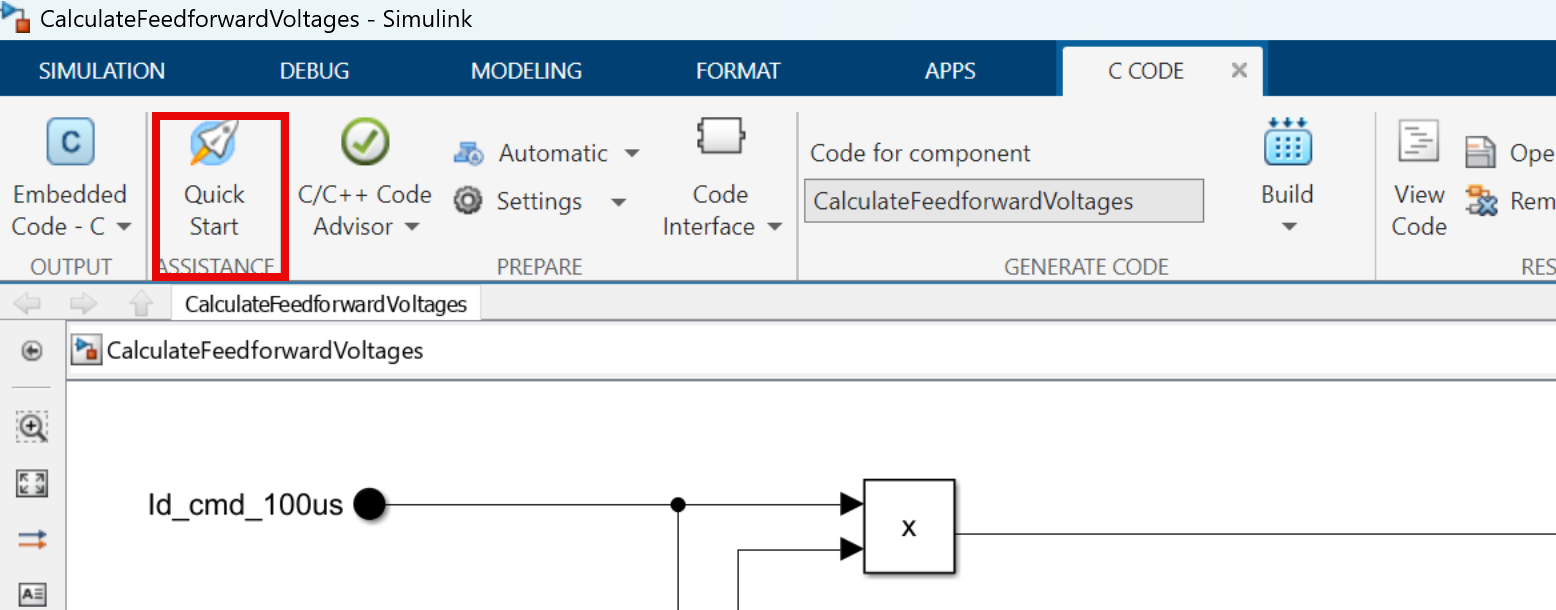

To start code generation for all behavior models, open **Process Advisor, **click **Run **next to Generate Code task.

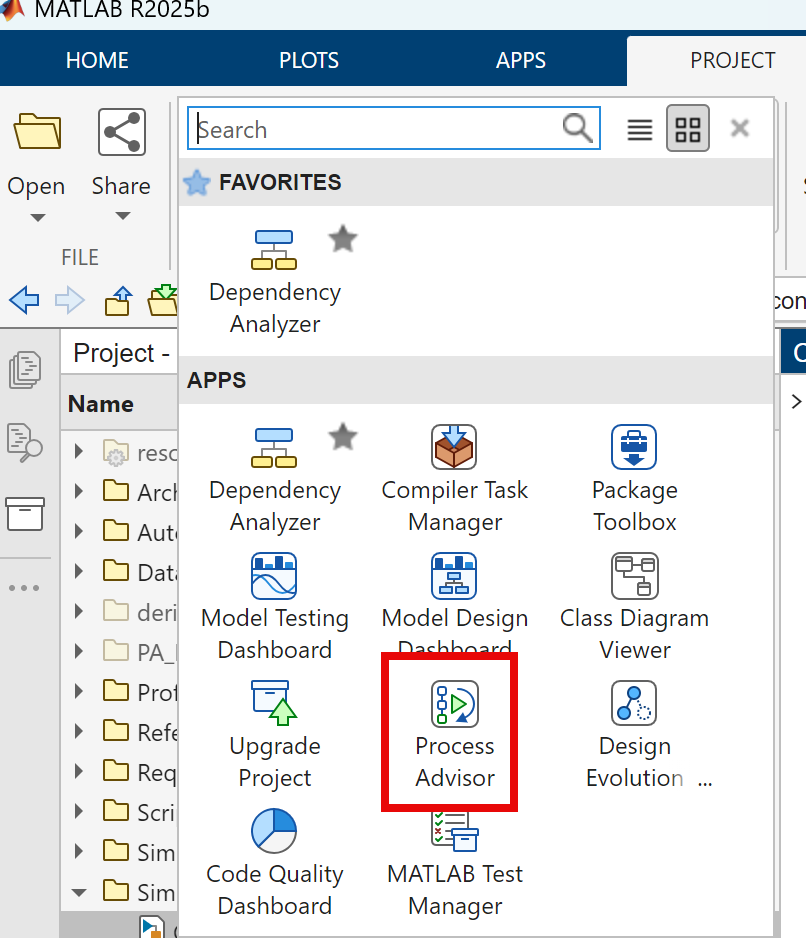         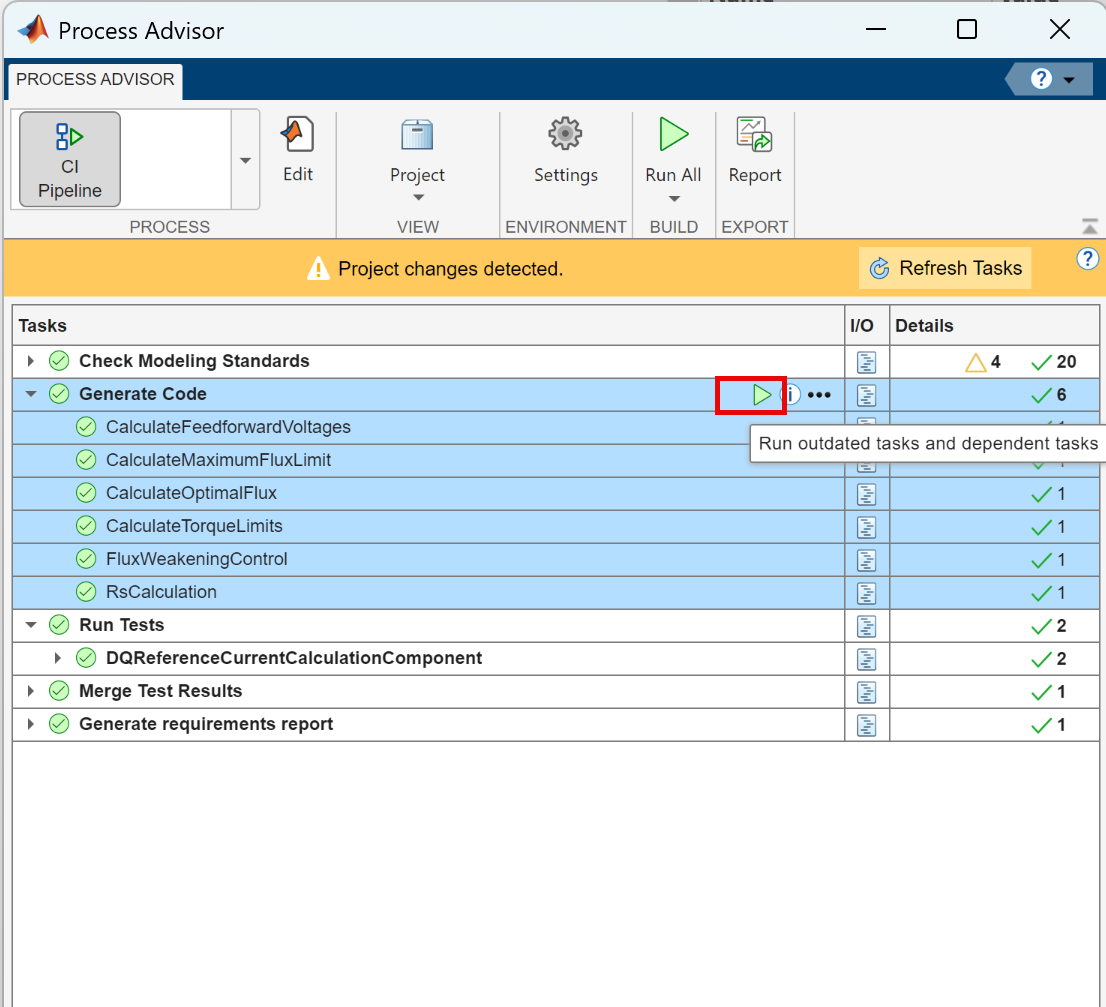

## 6.0 GitLab CI Pipeline Setup Using Processor Advisor

This workflow example demonstrates how to use **MATLAB Project**, **Process Advisor**, and **GitLab CI/CD** to generate and execute an example CI pipeline. 

To successfully set up the pipeline, you must first install and configure **GitLab Runner**. GitLab Runner is an application that executes the jobs defined in a GitLab CI/CD pipeline—such as checking model standards, generating code, and running tests.

Steps to set up a local GitLab Runner

- Install Git.

- Install Windows PowerShell (if not already available on your local machine).

- Install and configure Gitlab Runner locally. For detailed instructions, refer to inside page *“A Guide to Configuring a Local GitLab Runner for a Project.”*

Once set up, you can use the CI/CD configuration template file (`.gitlab-ci.yml`) provided by Process Advisor to define and generate pipelines. This template serves as a parent pipeline configuration that automatically calls the `padv.pipeline.generatePipeline` function to create an up-to-date child pipeline, which executes your process in CI. 

 With this approach, you do not need to manually write or maintain configuration files -- Any time your CI process or tasks change, simply update the **processmodel.m** file to refresh your pipeline automatically. 

When you push changes to the GitLab repository, it triggers the pipeline generation and execution of your CI process. 

You can further customize the pipeline by modifying the `script` section and using different [GitLabOptions](https://www.mathworks.com/help/slcheck/padv/ref/padv.pipeline.gitlaboptions.html) to tailor the generation process to your specific needs.

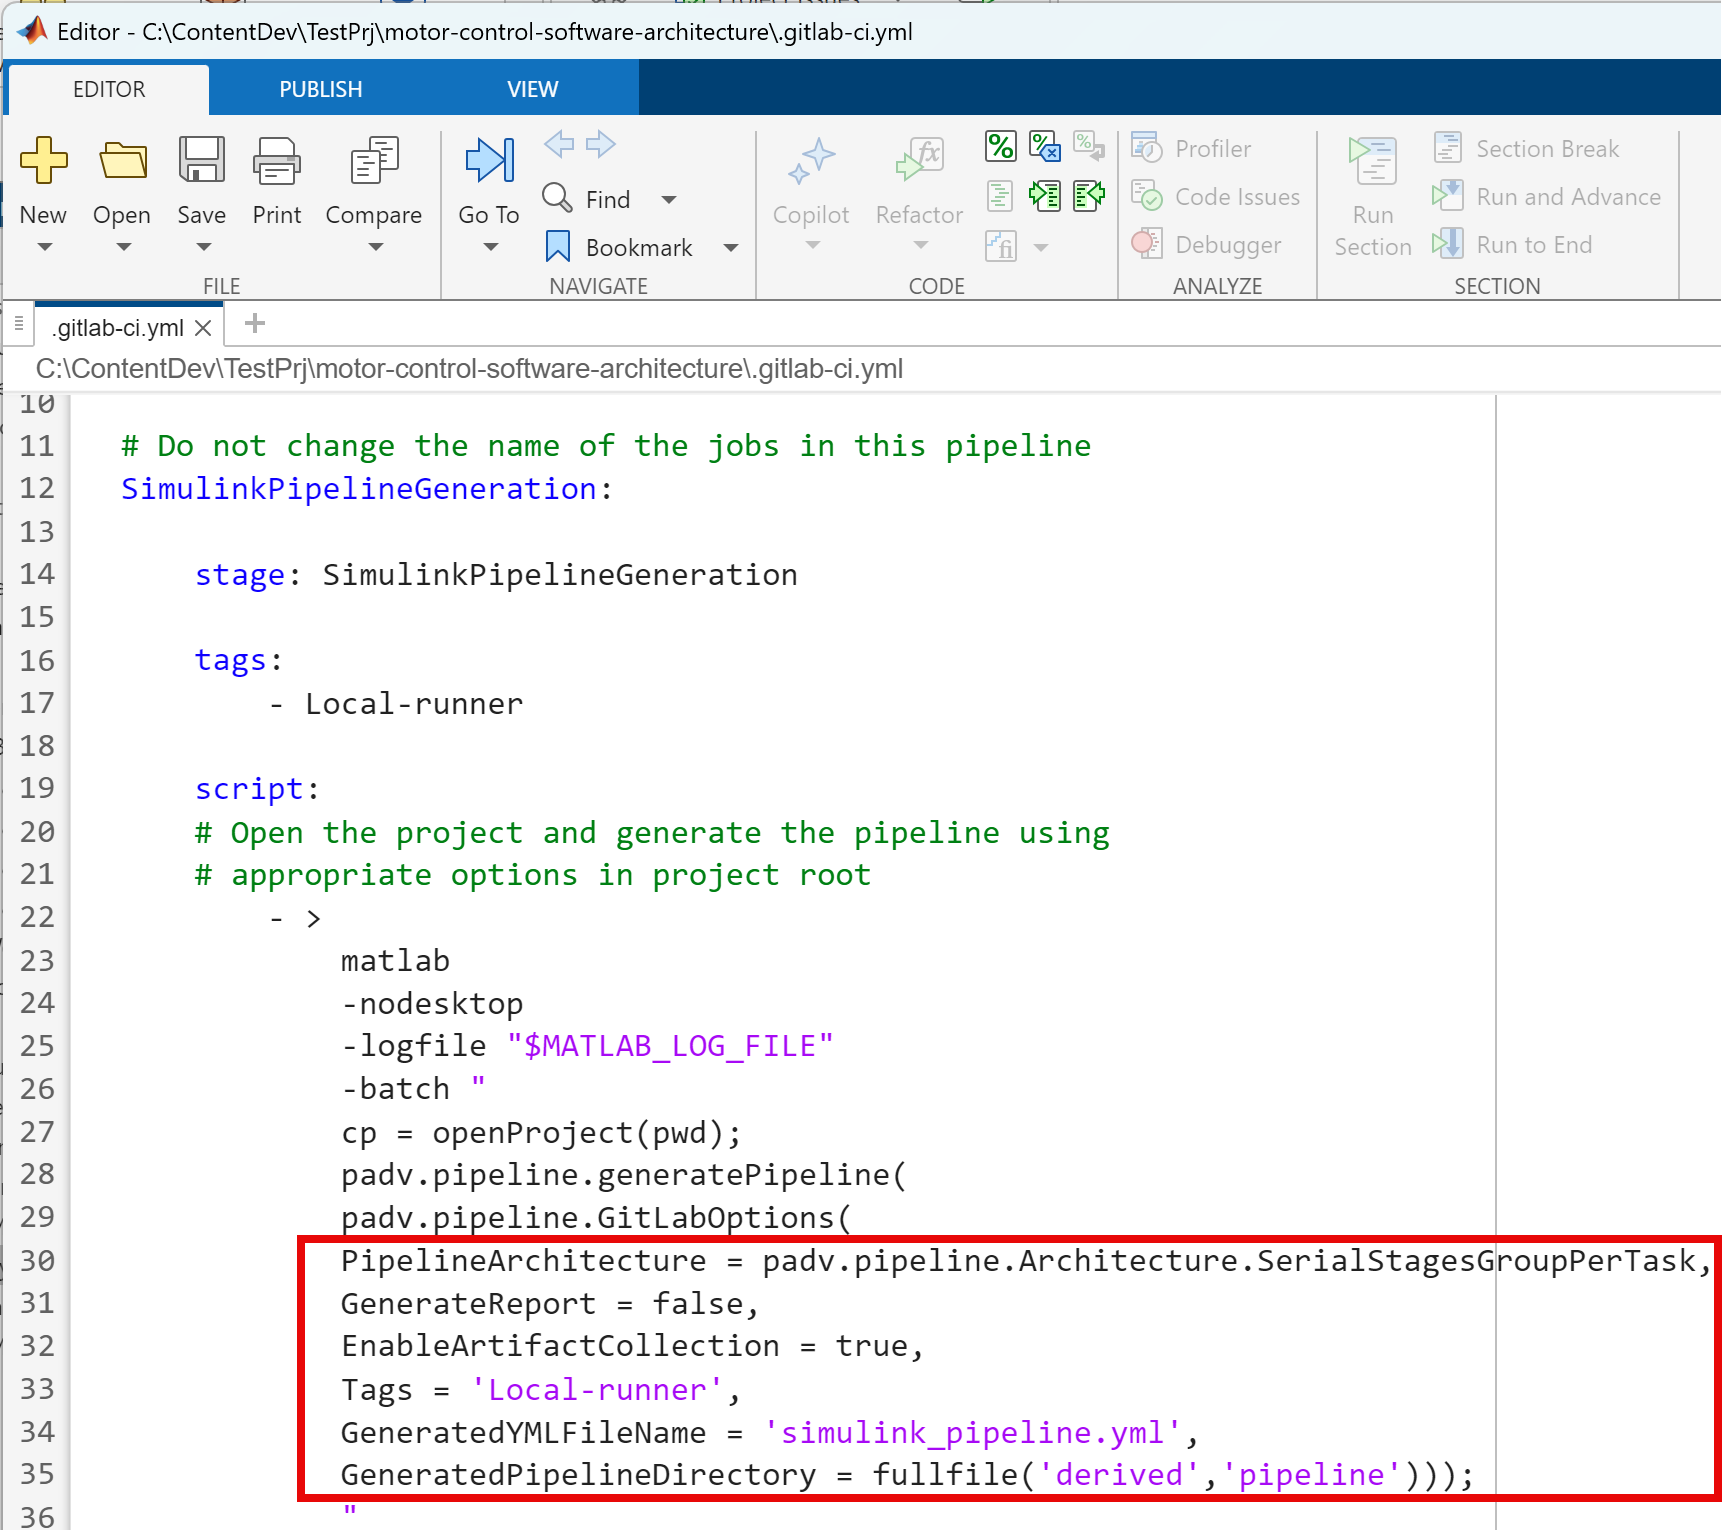

Within the pipeline, GitLab Runner leverages **matlab -batch **command to execute MBD tasks in a non-interactive manner. For example, running matlab -batch "myscript" from a command prompt starts MATLAB, executes the specified script, and then automatically closes when execution is complete. 

The pipeline tasks for this workflow example are defined in processmodel.m

In GitLab, once the pipeline completes, you can review the pipeline tasks, check their execution status and logs, and download any generated artifacts.

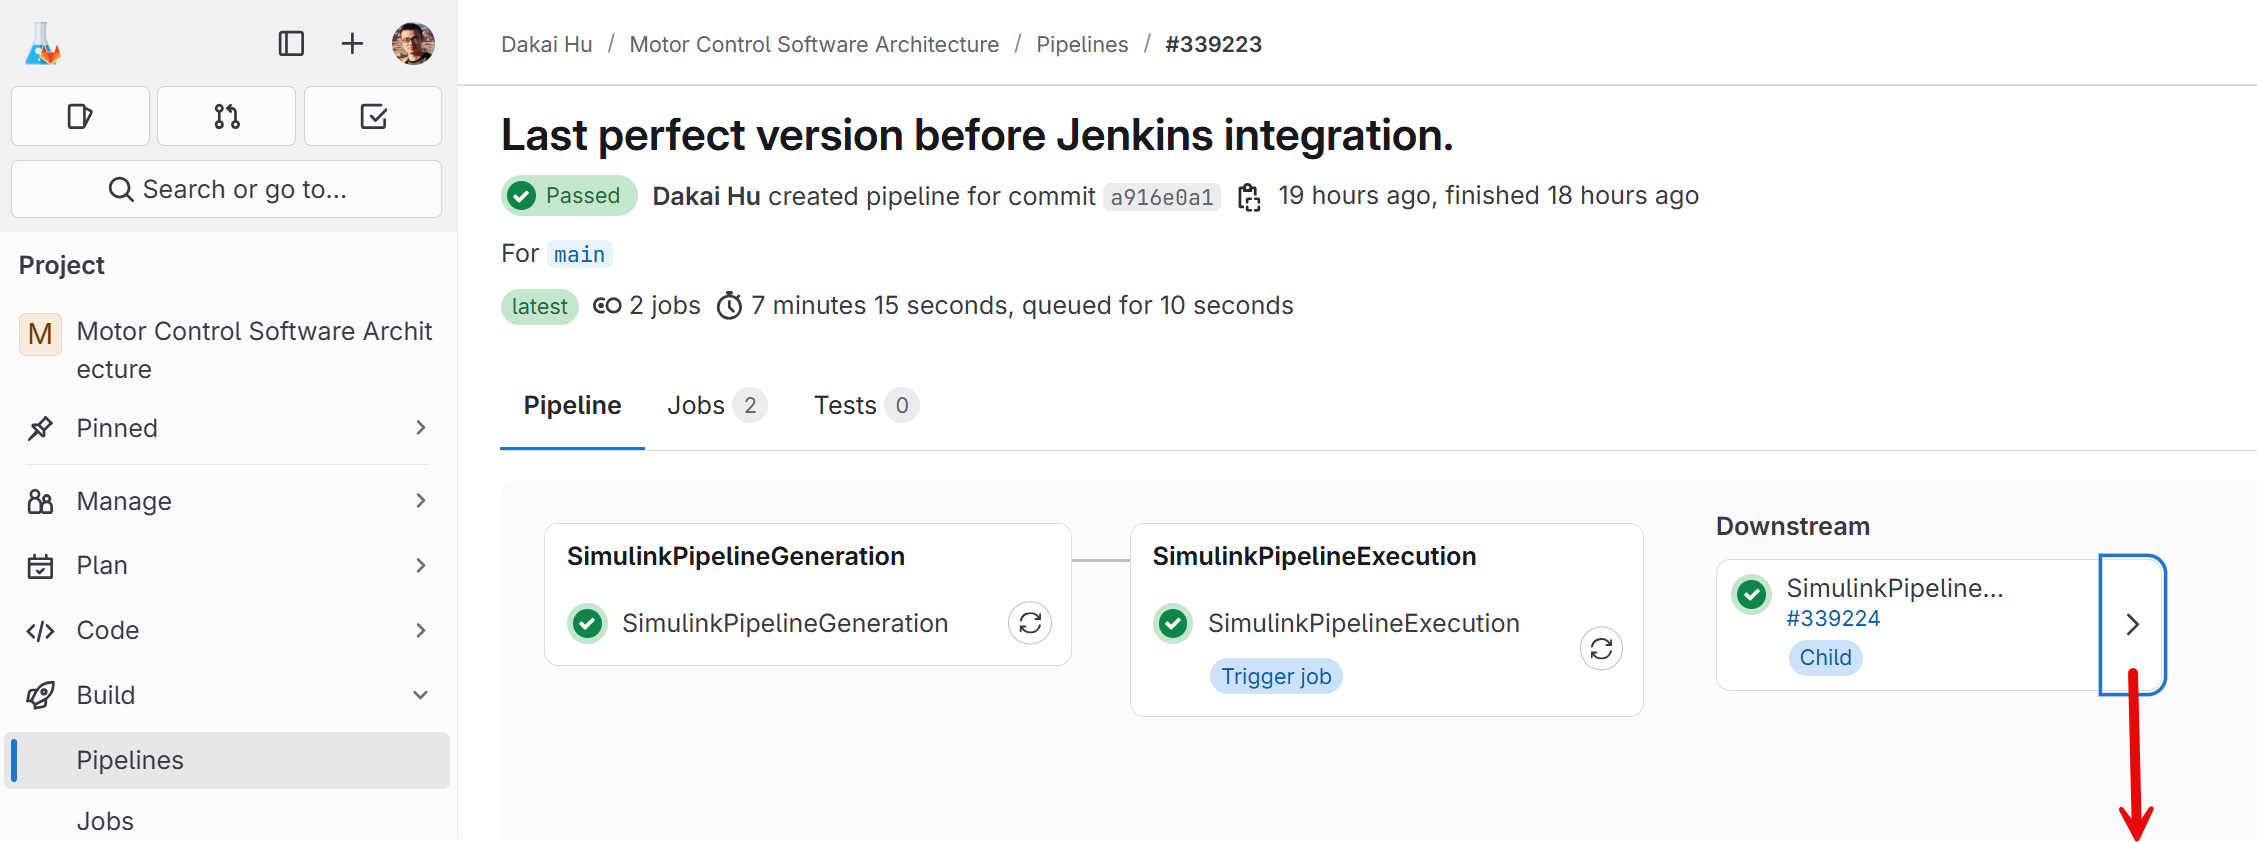

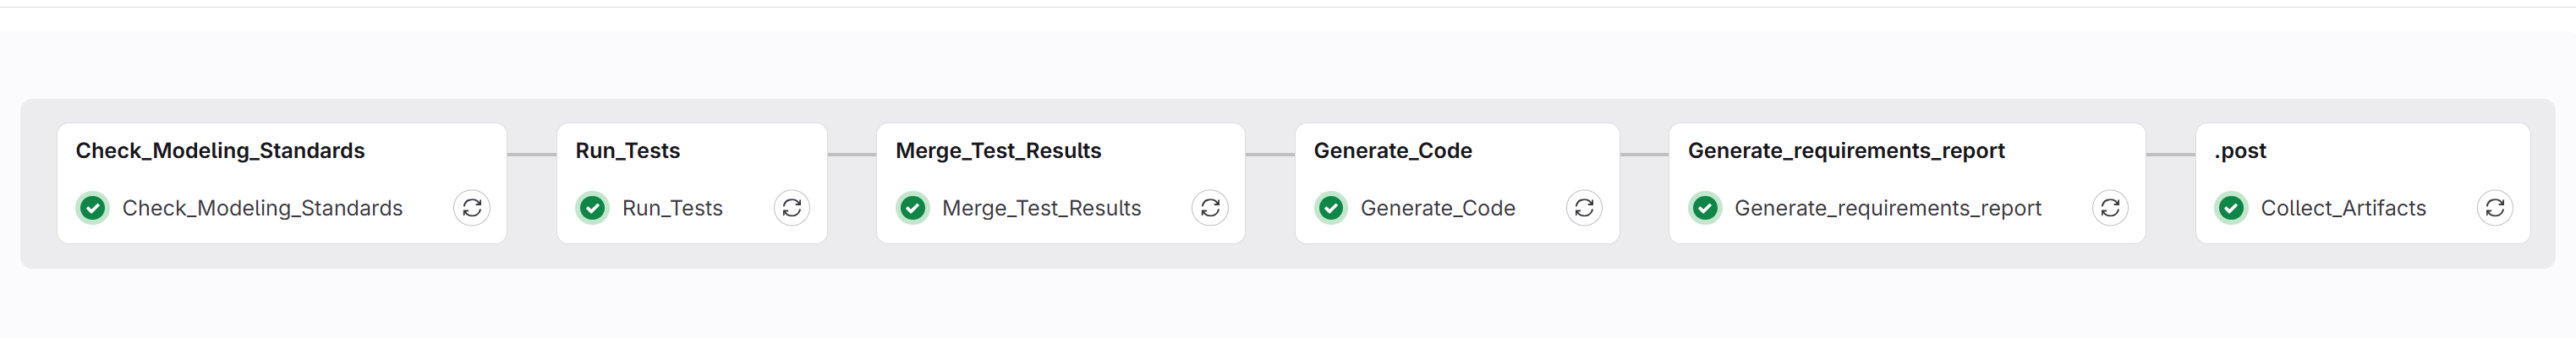

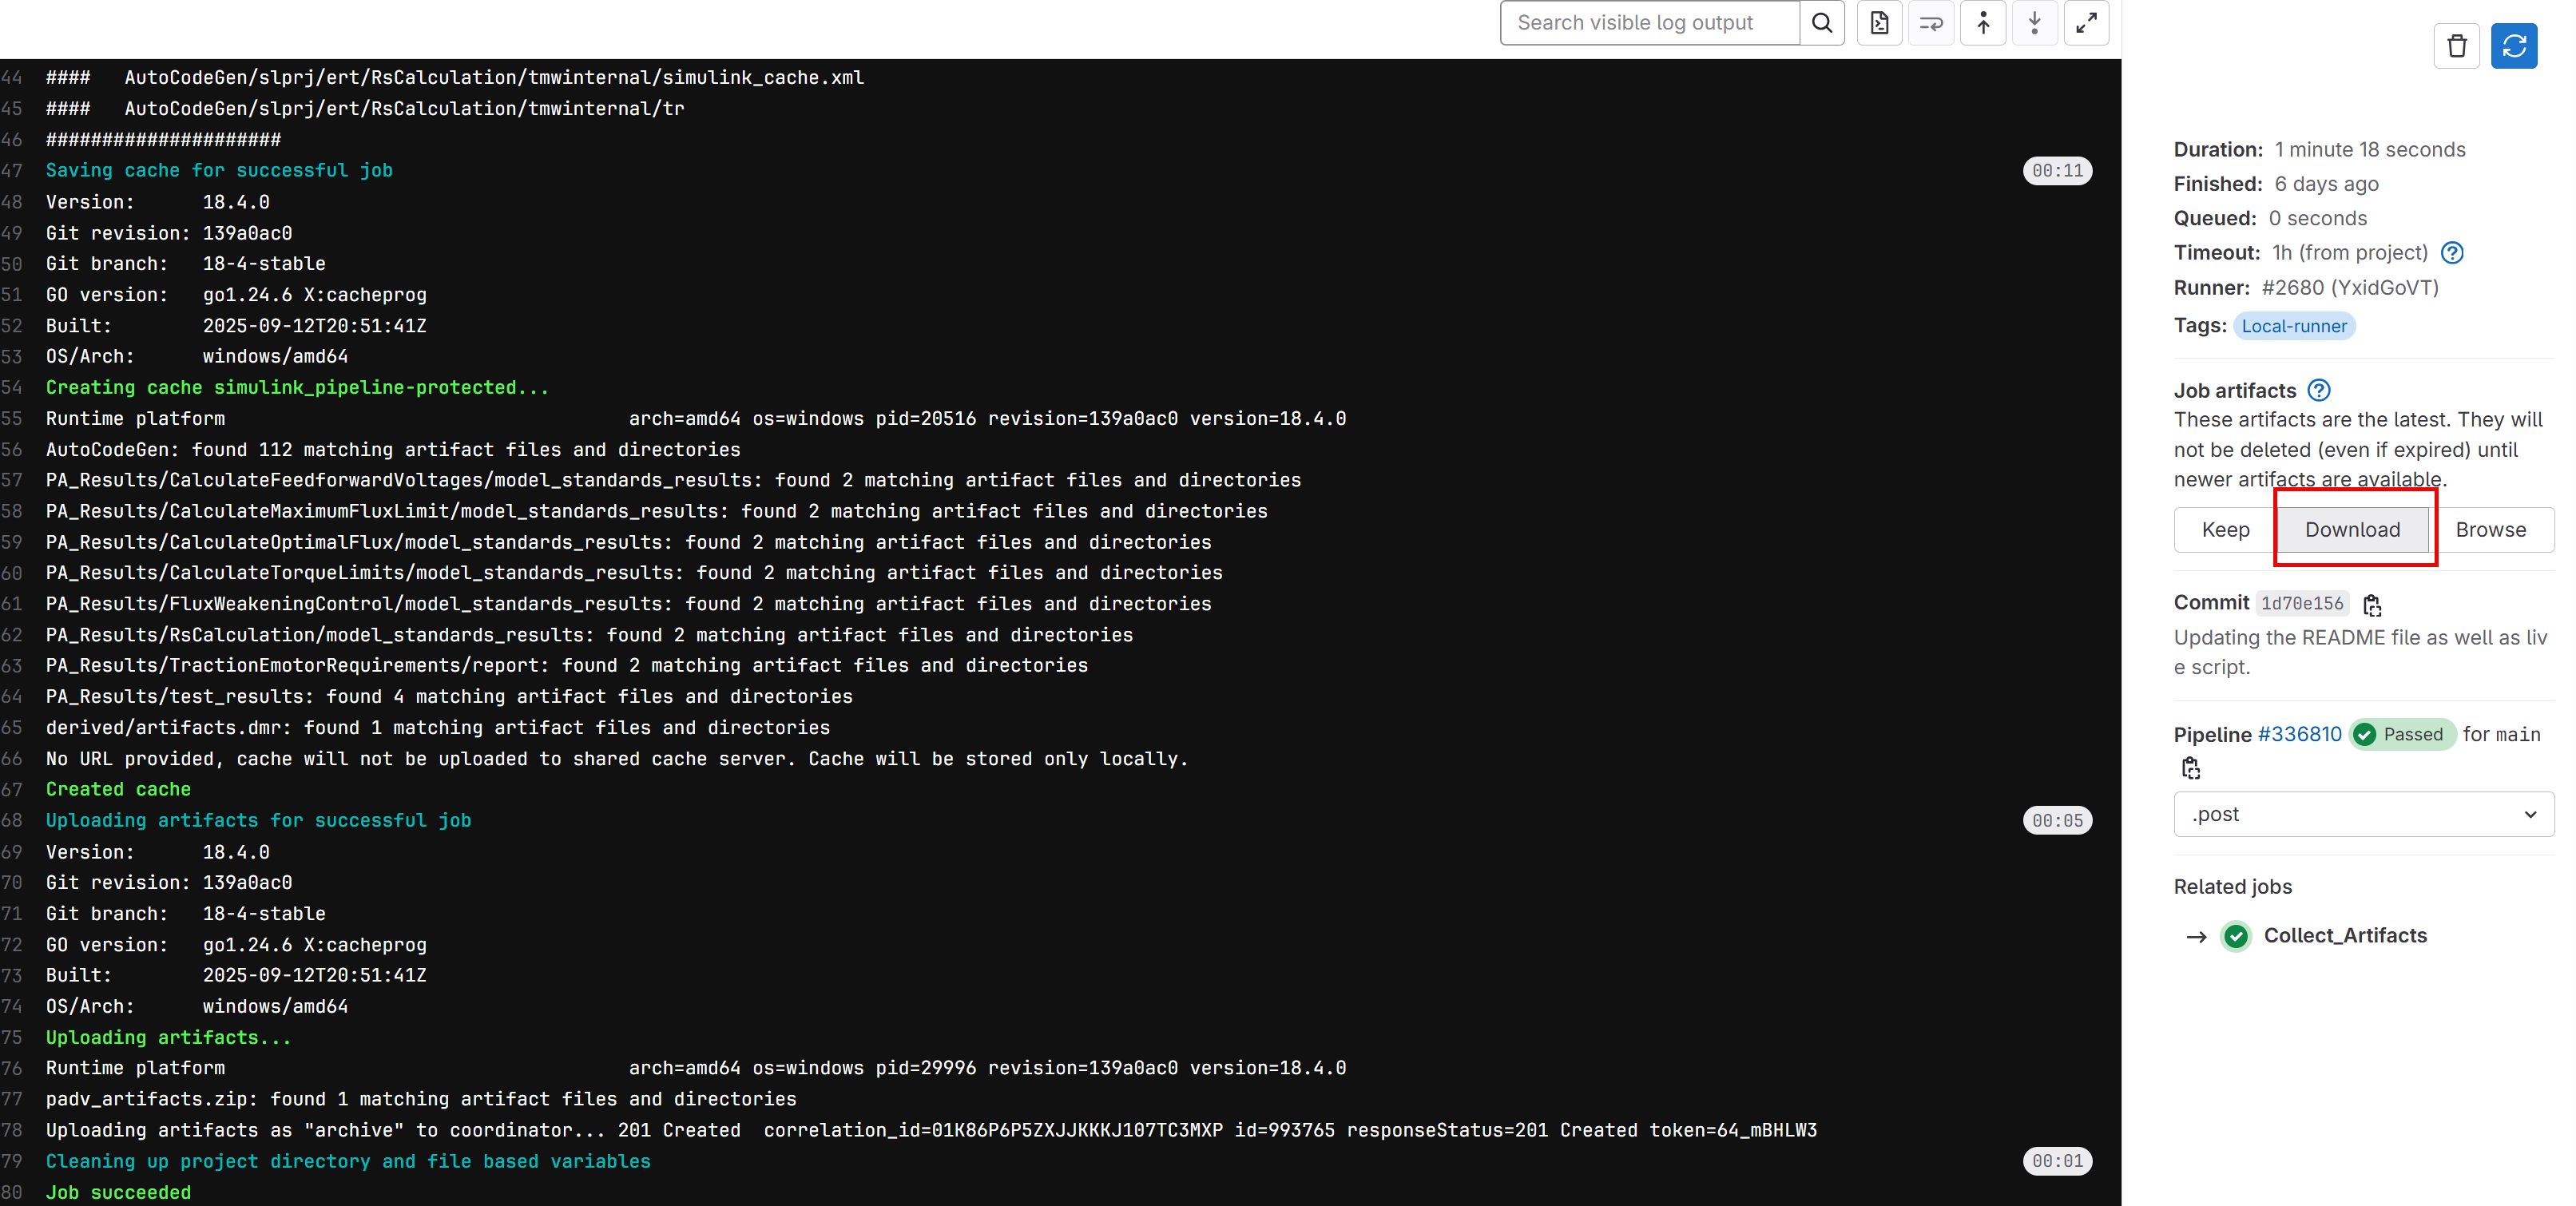

## 7.0 GitHub Actions CI Pipeline Setup Using Process Advisor

GitHub Actions provides free virtual machines (VMs) to run your CI/CD pipelines, depending on your account type (Free, Pro, Team, Enterprise) and whether the repository is public or private.  For private repositories (such as this example), you get 2000 free minutes/month for running jobs on Linux OS.

Here are the basic GitHub Actions CI Pipeline Setup steps:

- Copy the orignal MATLAB project into a new folder structure. 

- Connect MATLAB Project to GitHub repo.

- Create GitHub Actions secrets that contains your MATLAB Batch Licensing Token

- Create a .github/workflows directory on GitHub main page

- Generate Pipeline Configuration File: [https://www.mathworks.com/help/slcheck/padv/ug/integrate-into-github.html](https://www.mathworks.com/help/slcheck/padv/ug/integrate-into-github.html)

- Modify the above configuration file and place it under .github/workflows directory. 

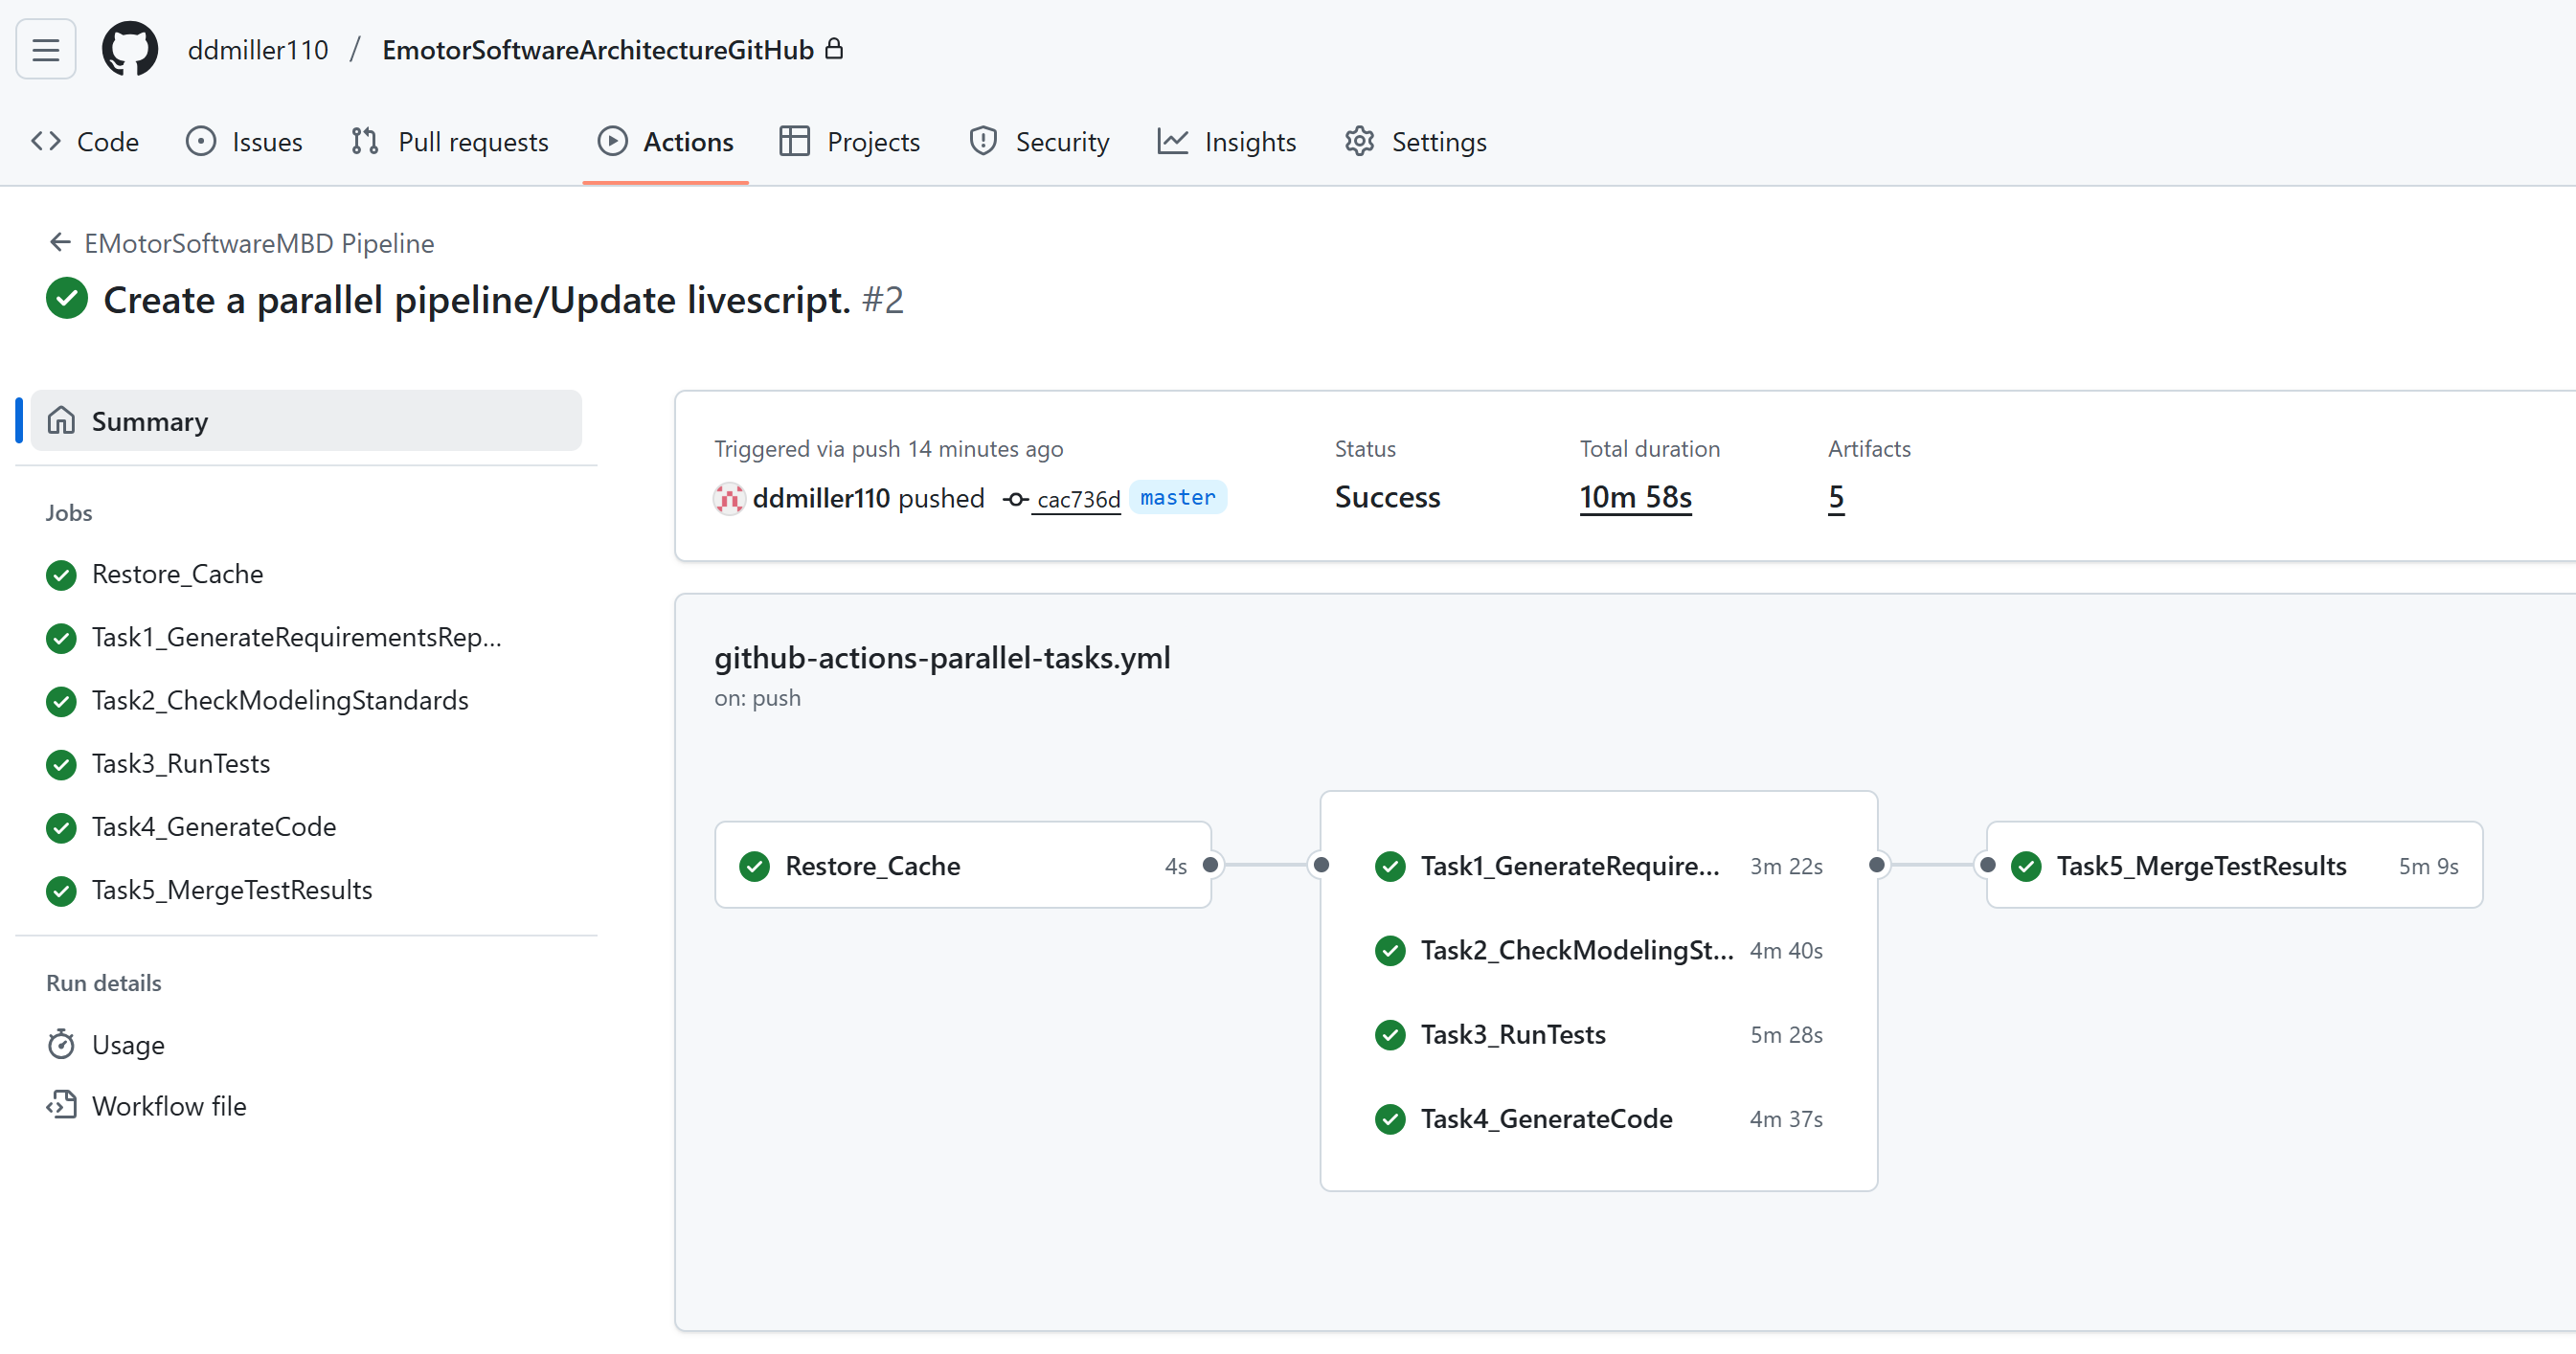

(Built using MATLAB R2025b, Copyright 2025 The MathWorks, Inc)